# *ME 599F - Robotics, Vision, Mechtronics for Manufacturing*

## Final Project: Keeranat Kolatat, Munzir Abdulmajid, Aditya Mahendru

**Problem 1**. [Visual servo control] A calibrated camera is initially posed at an unknown position and orientation in the world coordinate system. A board is visible inside the camera’s image view. Our goal is to design visual servo control algorithms to move the camera from its initial pose to a desired pose with respect to the board. Assume that the board coordinate system is the same as the world coordinate system. We have selected four feature points on the board (see the figure below). Based on the provided starting code, complete the following: 

   (a)  [position-based visual servo (PBVS)] The control law is given by (equation (18) in the reference paper): 	

										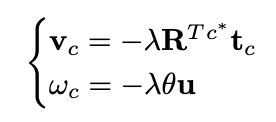		

where vc (3 × 1 vector) and ωc (3 × 1 vector) are the translational and rotational velocities of the camera w.r.t to the current camera frame, respectively. R is the 3 × 3 rotation matrix that gives the orientation of the current camera frame {C} w.r.t the desired camera frame {C∗} (i.e., {C∗} is the coordinate system attached to the camera when the camera is at the goal position and orientation). c∗tc is the 3×1 translation vector that gives the translation of {C} w.r.t {C∗}. θ (scalar) and u (3 × 1 unit vector) are, respectively, the angle and axis representation of the rotation matrix R. 

A possible realization of the above PBVS algorithm has been provided to you in starting_code.m in the project github repository. Run the algorithm. Observe the image plane trajectory, camera center trajectory and pose error plots. State your observation and analysis. 						

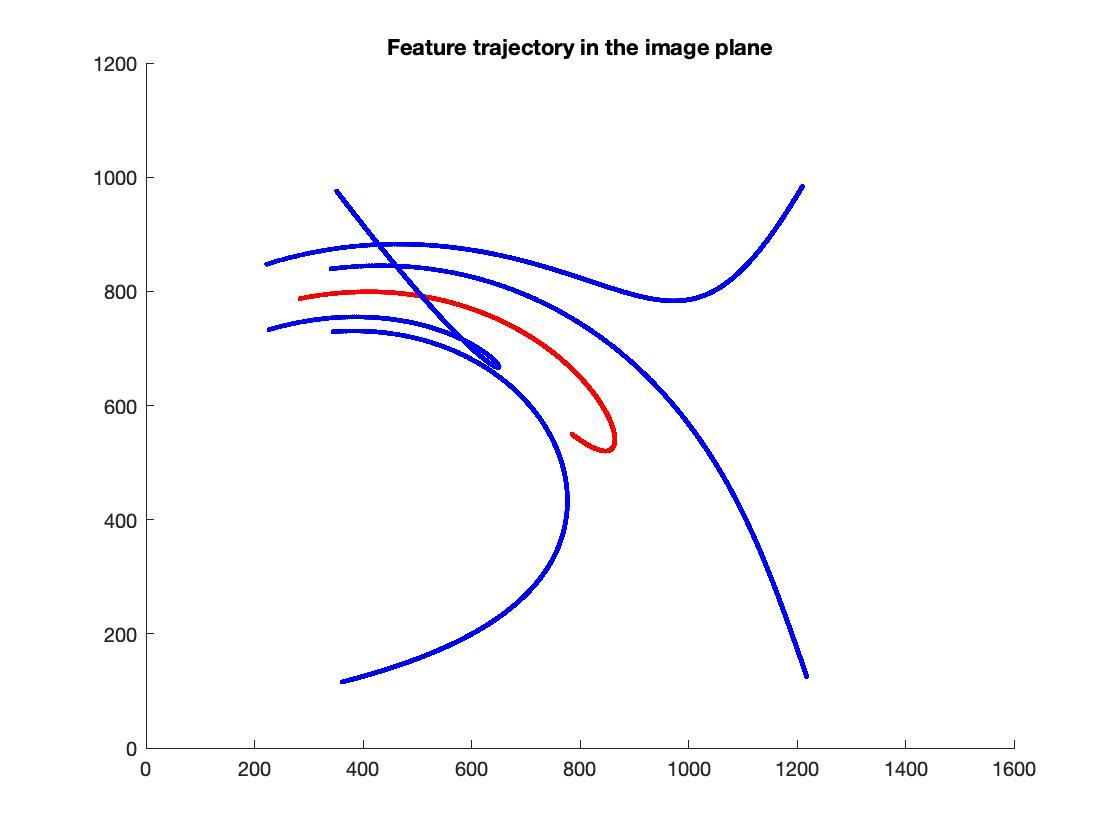

This figure shows the image plane of the feature. Here, the feature is a board, and the four corners of the board are identified. The trajectory paths are shown in the blue lines on the image plane, and the red line is the center of the board. 

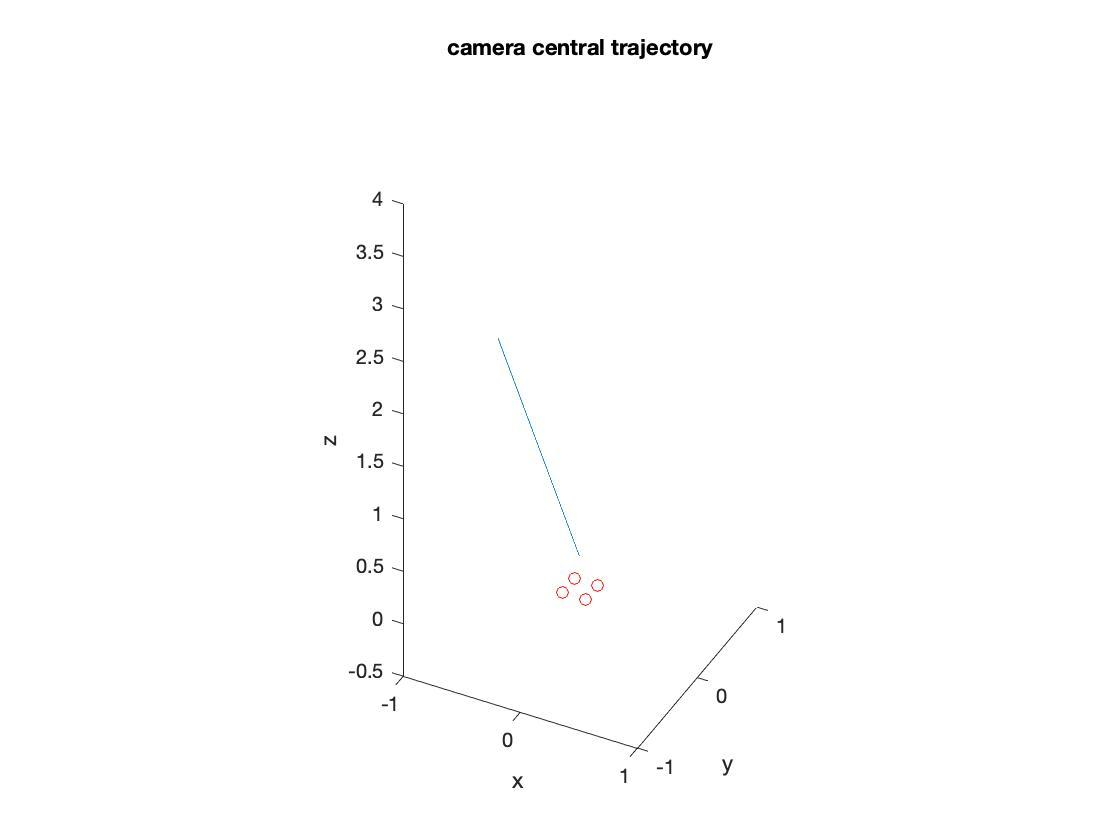

The second figure shows the center of the camera trajectory in the 3D world points. The blue line is the trajectory path of the camera, and the four circles are four corners of the board in the world points.

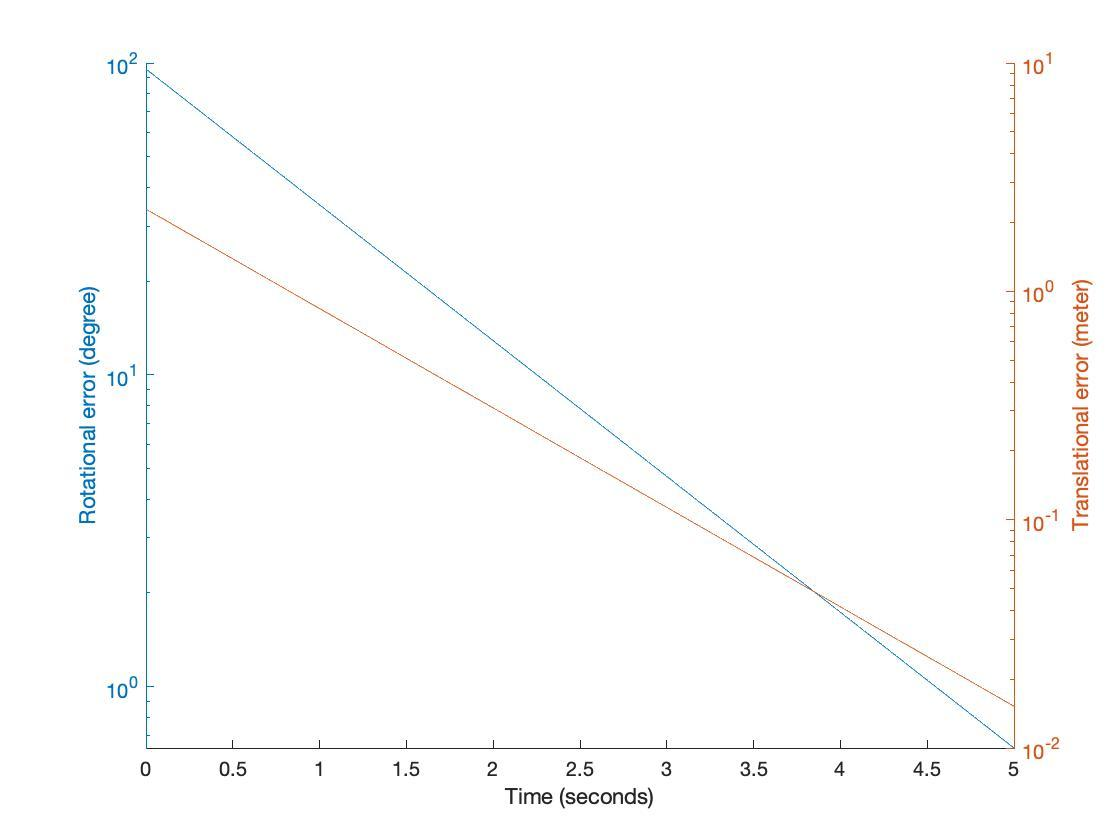

The third figure shows the error of the current camera position relative to the desired position of the camera. The pose error decreases as the camera approaches the desired position. The error is in log scale, and the linear decrease in error on the log scale indicates that the camera is converging towards an error of 0 in the rotational and translational error.

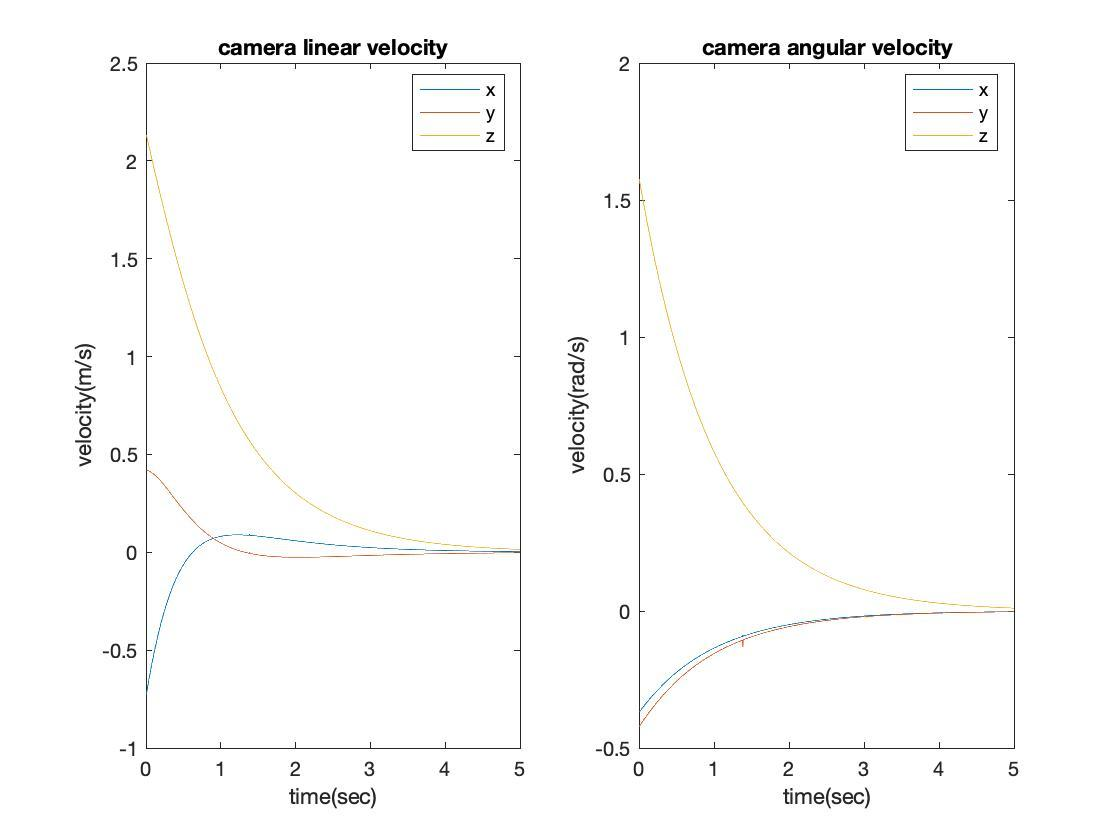

The final figure shows the velocity and angular velocities of the camera in the x, y & z. The velocities approach 0 as the camera approaches the pose.							

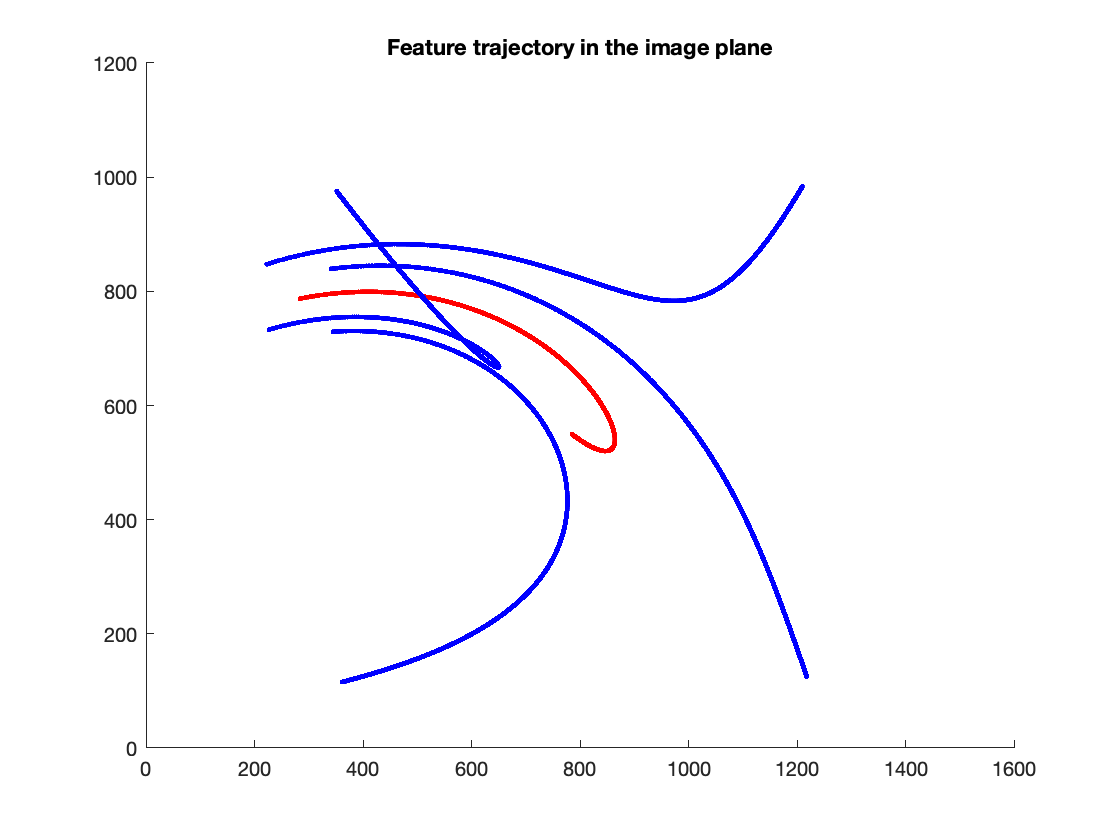

% University of Washington
% Mechanical Engineering
% Robotics, Vision, and Mechatronics for Manufacturing, 2021 Sp
% 
% required toolbox:
%   Robotics toolbox from Peter Corke.
%   Computer Vision toolbox from Mathworks (to use pose estimation function).
%   Statistics and Machine Learning Toolbox from Mathworks (to generate
%       Gaussian noise)

clear all
close all
clc

%% set camera model
camera.K = [1349.056772980567, 0, 774.9519749992618;
            0, 1351.558896220857, 557.5626838601945;
            0, 0, 1];
camera.img_size = [1600, 1200];
camera_param = cameraIntrinsics([camera.K(1,1), camera.K(2,2)],...
                                [camera.K(1,3), camera.K(2,3)], ...
                                camera.img_size);

%% environment setup
% featuer points' coordinates w.r.t the board frame
featurePositions = [-0.1, -0.1, 0.1, 0.1; 
                    -0.1, 0.1,  0.1, -0.1; 
                    0,    0,    0,   0];
         
% the desired pose of board w.r.t camera (4x4 matrix)
goal_camera2board_pose = transl(0,0,0.3)*trotx(pi);

% camera's initial pose w.r.t the board frame (4x4 matrix)
% don't use this vairable in your algorithm
% it is assumed unknown
init_board2camera_pose = transl(-0.5,-0.4,2.5)*trotz(1.6)*trotx(3.1)*troty(0.5);

%% simulation
step_size = 0.005;          % simulation step size in seconds
sim_time = 5;               % simulation duration in seconds
N_steps = sim_time/step_size;

% initialize the state object
% the state object describes all state variables at a time
state_obj = state(init_board2camera_pose, camera, featurePositions);
state_obj2 = state_obj;
state_obj_fix = state_obj; %IBVS fixed depth
state_obj_Z11 = state_obj; %IBVS 1.1 fixed depth
state_obj_Z13 = state_obj; %IBVS 1.3 fixed depth
state_obj_Z15 = state_obj; %IBVS 1.5 fixed depth
state_obj_Z2 = state_obj; %IBVS 2.0 fixed depth
state_obj_PBVS = state_obj; %PBVS noisy
state_obj_IBVS = state_obj; %IBVS noisy feature depth

% we create a cell array to save state object at each time step.
data = cell([N_steps,1]);
data2 = data;
data3 = data;
data4 = data;
data5 = data;
data6 = data;
data7 = data;
data8 = data;
data9 = data;

% simulation start.
k = 0;
lambda = 1;
for t = step_size:step_size:sim_time
    k = k + 1;
    % Step 1: compute (by simulation) the image coordinates of projected 
    % feature points
    [state_obj, imgPoints] = state_obj.project();
    [state_obj2, imgPoints2] = state_obj2.project();
    [state_obj_fix, imgPoints3] = state_obj_fix.project();
    [state_obj_Z11, imgPoints4] = state_obj_Z11.project();
    [state_obj_Z13, imgPoints5] = state_obj_Z13.project();
    [state_obj_Z15, imgPoints6] = state_obj_Z15.project();
    [state_obj_Z2, imgPoints7] = state_obj_Z2.project();
    [state_obj_PBVS, imgPoints8] = state_obj_PBVS.project();
    [state_obj_IBVS, imgPoints9] = state_obj_IBVS.project();
    
    % Step 2: visual servo step to compute desired camera velocity.
    
    %===========================
    % Your code starts from here
    % You should obtain desired camera velocity (w.r.t to camera frame)
    % cam_vel (6x1 vector) based on the obtained feature points in the image.

    % ---- PBVS without pose estimation noises -----
    % A possible PBVS_step function is written at the end of this file to
    % compute the camera velocity vector under a PBVS algorithm.
    cam_vel = PBVS_step(imgPoints, camera, featurePositions, goal_camera2board_pose, lambda, 1);
    
    % ---- IBVS (using the goal depth) -----
    % This is an example code structure. You will need to write your own IBVS_step function.
    cam_vel2 = IBVS_step(imgPoints2, camera, featurePositions,...
                        goal_camera2board_pose,state_obj2,lambda,1,1,camera_param);

    % ---- IBVS (using the true depth) -----
    %Z = state_obj_fix.getFeatureDepth();
    cam_vel3 = IBVS_step(imgPoints3, camera, featurePositions,...
                        goal_camera2board_pose,state_obj_fix,lambda,0,1,camera_param);
    
    % test the case with different Z values
    cam_vel4 = IBVS_step(imgPoints4, camera, featurePositions,...
                        goal_camera2board_pose,state_obj_Z11,lambda,0,1.1,camera_param);
    cam_vel5 = IBVS_step(imgPoints5, camera, featurePositions,...
                        goal_camera2board_pose,state_obj_Z13,lambda,0,1.3,camera_param);
    cam_vel6 = IBVS_step(imgPoints6, camera, featurePositions,...
                        goal_camera2board_pose,state_obj_Z15,lambda,0,1.5,camera_param);
    cam_vel7 = IBVS_step(imgPoints7, camera, featurePositions,...
                        goal_camera2board_pose,state_obj_Z2,lambda,0,2,camera_param);
    
    % ---- PBVS and IBVS with noises in pose estimation -----
    imgPoints_noisy = imgPoints8 + normrnd(0,5,size(imgPoints));
    imgPoints_noisy2 = imgPoints9 + normrnd(0, 5, size(imgPoints));
    cam_vel8 = PBVS_step(imgPoints_noisy, camera, featurePositions, goal_camera2board_pose, lambda, 1);
    cam_vel9 = IBVS_step(imgPoints_noisy2, camera, featurePositions, goal_camera2board_pose,state_obj_IBVS,lambda,1,2,camera_param);
    % your code ends here.
    %====================
    
    % Step 3: update camera position. We assume a perfect motion
    % controller. That is, the actual camera velocity equals to the desired
    % camera velocity given by the visual servo step. We assume that the 
    % camera is moving with a constant speed during the step_size time.
    state_obj = state_obj.step(cam_vel, step_size);
    state_obj2 = state_obj2.step(cam_vel2, step_size);
    state_obj_fix = state_obj_fix.step(cam_vel3, step_size);
    state_obj_Z11 = state_obj_Z11.step(cam_vel4, step_size);
    state_obj_Z13 = state_obj_Z13.step(cam_vel5, step_size);
    state_obj_Z15 = state_obj_Z15.step(cam_vel6, step_size);
    state_obj_Z2 = state_obj_Z2.step(cam_vel7, step_size);
    state_obj_PBVS = state_obj_PBVS.step(cam_vel8, step_size);
    state_obj_IBVS = state_obj_IBVS.step(cam_vel9, step_size);
    
    % save current state. 
    
    data{k} = state_obj;
    data2{k} = state_obj2;
    data3{k} = state_obj_fix;
    data4{k} = state_obj_Z11;
    data5{k} = state_obj_Z13;
    data6{k} = state_obj_Z15;
    data7{k} = state_obj_Z2;
    data8{k} = state_obj_PBVS;
    data9{k} = state_obj_IBVS;
end
% simulation end.

%% analysis and visulize data

%% % Plot image plane trajectory % %
figure,
hold on
num_data = size(data,1);
for i = 1:num_data
    imgPoints = data{i}.imagePoints;
    plot(imgPoints(1,:),imgPoints(2,:),'.b');
    plot(mean(imgPoints(1,:)), mean(imgPoints(2,:)), '.r');
    axis([0 1600 0 1200]);
end
title('Feature trajectory in the image plane')

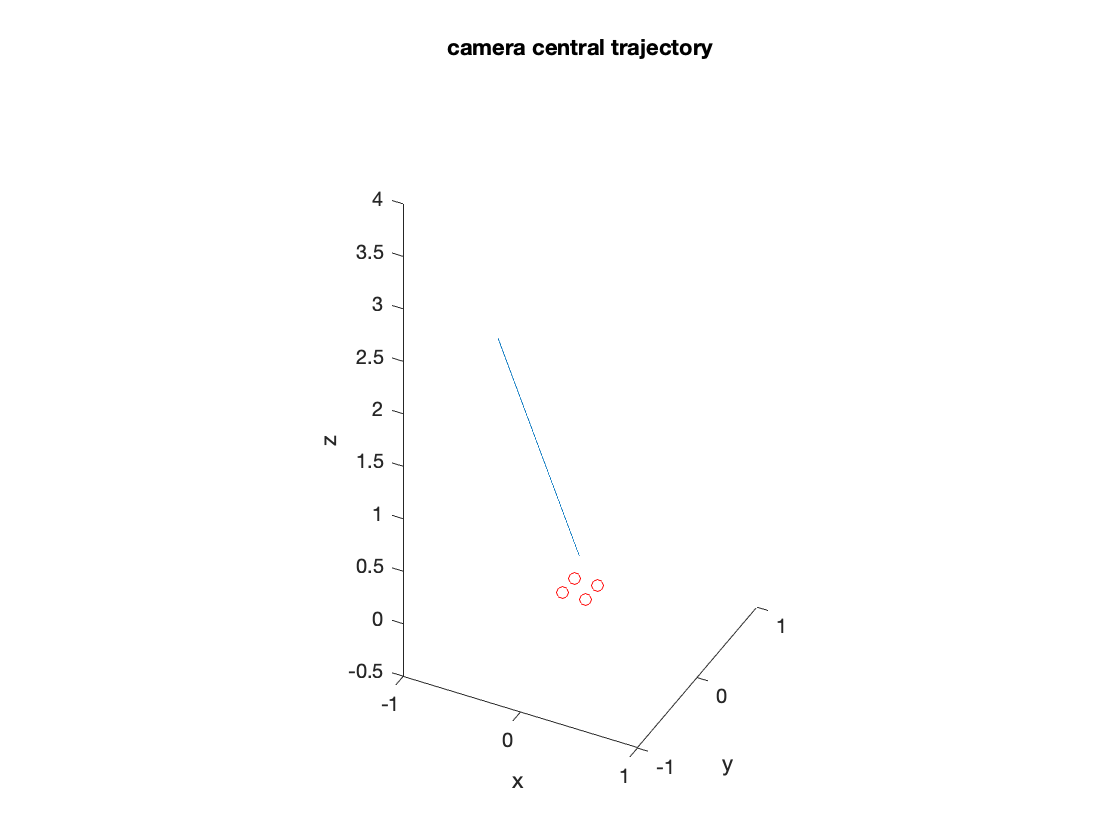

% Red line is the trajectory of the feature center.

%% % Plot camera center trajectory % %
camera_central.x = zeros(num_data,1);
camera_central.y = zeros(num_data,1);
camera_central.z = zeros(num_data,1);
camera_central.time = zeros(num_data,1);
for i = 1:num_data
    cameraPose = data{i}.cameraPose;
    camera_central.x(i) = cameraPose(1,4);
    camera_central.y(i) = cameraPose(2,4);
    camera_central.z(i) = cameraPose(3,4);
    camera_central.time(i) = data{i}.time;
end
figure,
hold on
plot3(camera_central.x, camera_central.y, camera_central.z);
hold on
plot3(featurePositions(1,:), featurePositions(2,:), featurePositions(3,:), 'or');
xlabel('x');
ylabel('y');
zlabel('z');
axis([-1 1 -1 1 0 4])
title('camera central trajectory');
view(27,37)
axis equal
xlim([-1 1])
ylim([-1 1])
zlim([-0.5 4])

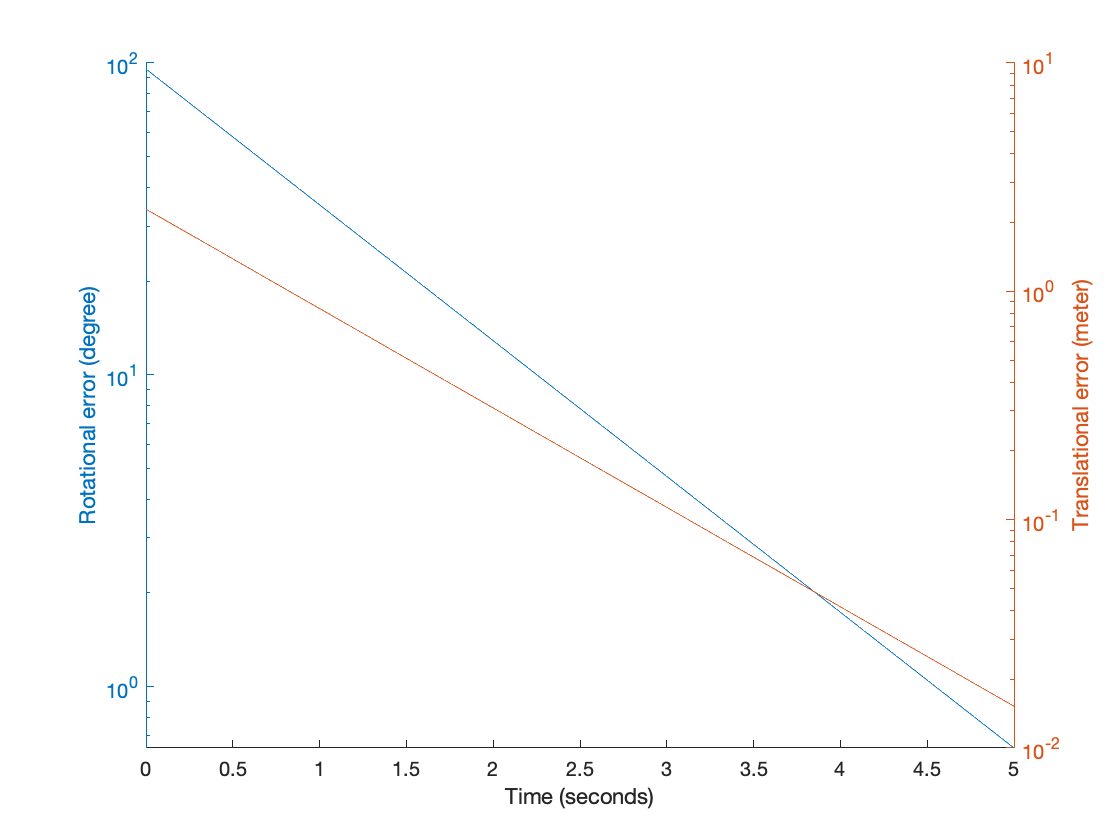


%% plot pose error vs time
rotation_error = zeros(N_steps, 1);
translation_error = zeros(N_steps,1);
time = zeros(N_steps,1);
for i = 1:num_data
    cam_pose = data{i}.cameraPose;
    error_pose = goal_camera2board_pose * cam_pose;
    
    translation_error(i) = norm(tform2trvec(error_pose));
    angaxis = tform2axang(error_pose);
    rotation_error(i) = abs(angaxis(4));
    time(i) = data{i}.time;
end
figure,
hold on
yyaxis left
plot(time, rotation_error*180/pi);
set(gca, 'YScale', 'log')
ylabel('Rotational error (degree)')
yyaxis right
plot(time, translation_error);
set(gca, 'YScale', 'log')
ylabel('Translational error (meter)');
xlabel('Time (seconds)')

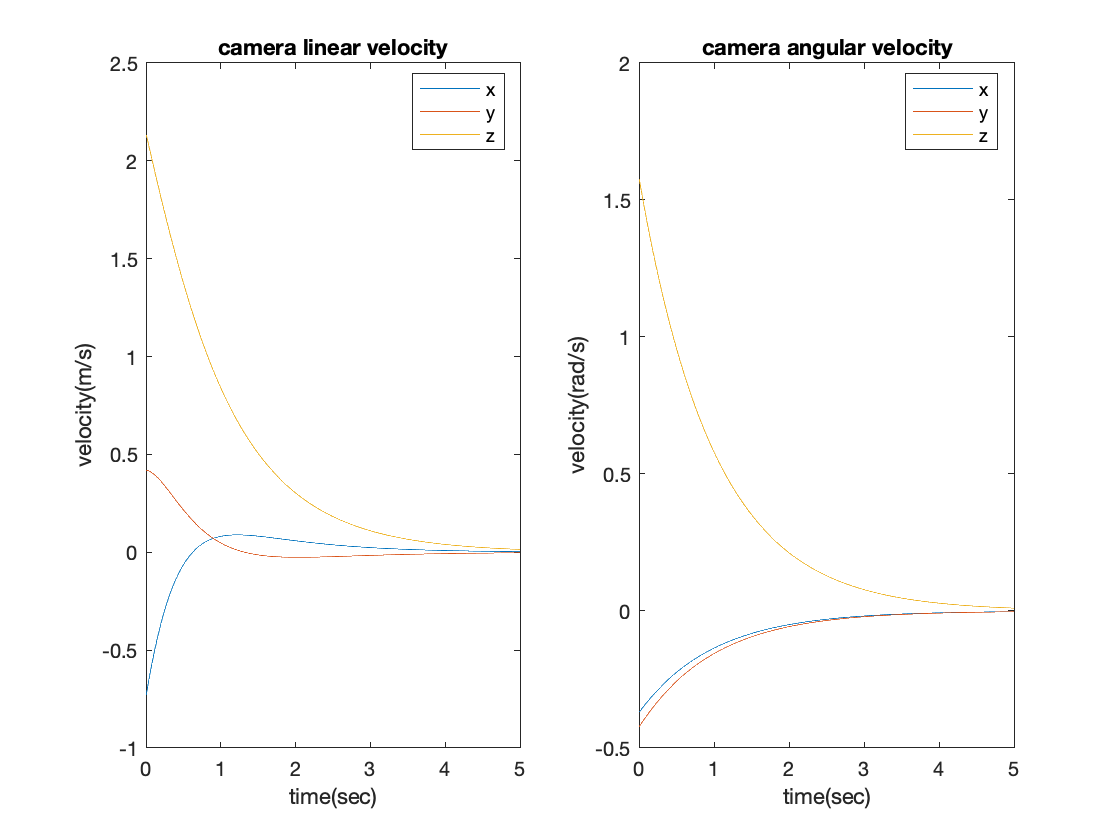


%% plot camera velocity
figure,
cam_velocity.time = zeros(N_steps, 1);
cam_velocity.l.x = zeros(N_steps, 1);
cam_velocity.l.y = zeros(N_steps, 1);
cam_velocity.l.z = zeros(N_steps, 1);
cam_velocity.a.x = zeros(N_steps, 1);
cam_velocity.a.y = zeros(N_steps, 1);
cam_velocity.a.z = zeros(N_steps, 1);
for i = 1:N_steps
    cam_vel = data{i}.cam_vel;
    cam_velocity.time(i) = data{i}.time;
    cam_velocity.l.x(i) = cam_vel(1);
    cam_velocity.l.y(i) = cam_vel(2);
    cam_velocity.l.z(i) = cam_vel(3);
    cam_velocity.a.x(i) = cam_vel(4);
    cam_velocity.a.y(i) = cam_vel(5);
    cam_velocity.a.z(i) = cam_vel(6);
end
subplot(1,2,1)
plot(cam_velocity.time, cam_velocity.l.x);
hold on
plot(cam_velocity.time, cam_velocity.l.y);
plot(cam_velocity.time, cam_velocity.l.z);
xlabel('time(sec)')
ylabel('velocity(m/s)');
title('camera linear velocity');
legend('x','y','z','Location','best');
subplot(1,2,2)
plot(cam_velocity.time, cam_velocity.a.x);
hold on
plot(cam_velocity.time, cam_velocity.a.y);
plot(cam_velocity.time, cam_velocity.a.z);
xlabel('time(sec)')
ylabel('velocity(rad/s)');
title('camera angular velocity');
legend('x','y','z','Location','best');									

(b)  [image-based visual servo (IBVS)] The control law is given by (15.11) in the textbook. 						

i. Implement the IBVS algorithm. Use the true feature depth to construct the image Jacobians: Use Z = state_obj.getFeatureDepth() to obtain the true feature depth (1 × 4 vector) at each simulation step. Observe the image plane trajectory, camera center trajectory and pose error plots. Compare them with the PBVS results in part (a). State your observation and analysis. 	

% Part B i
    section = 'Part B i'

section = 'Part B i'

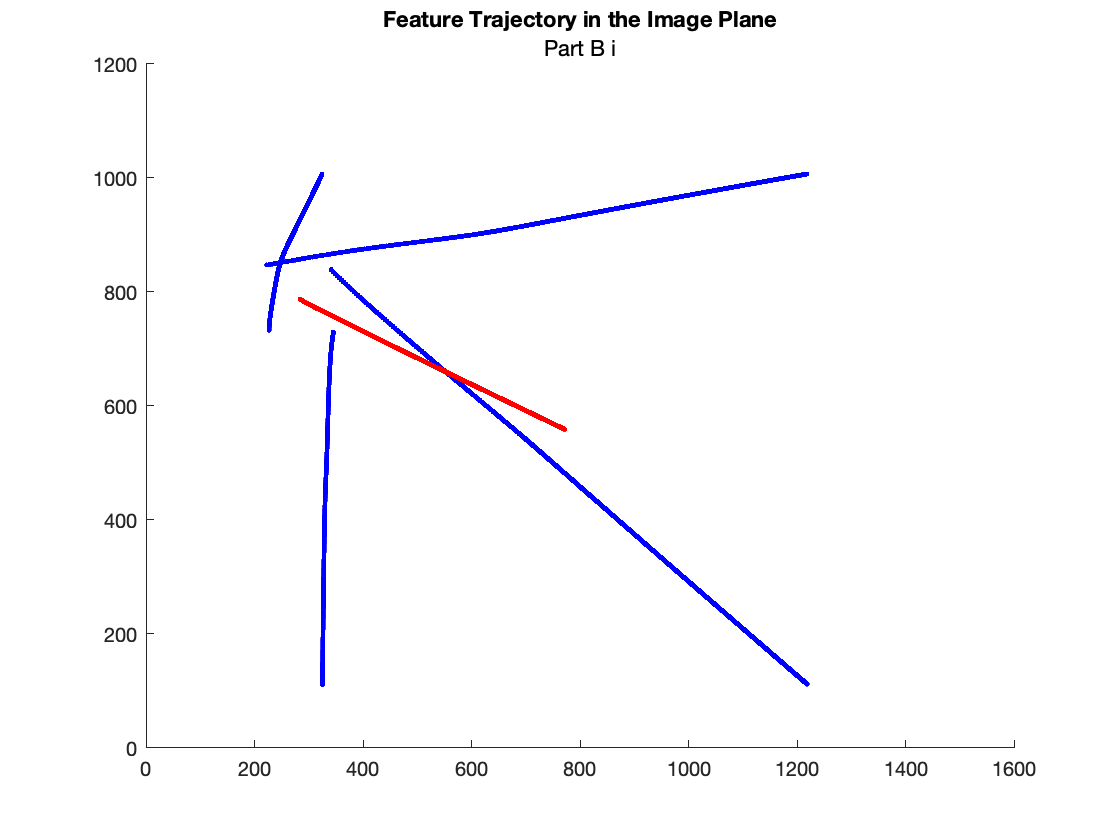

    imgplot(data2, section)

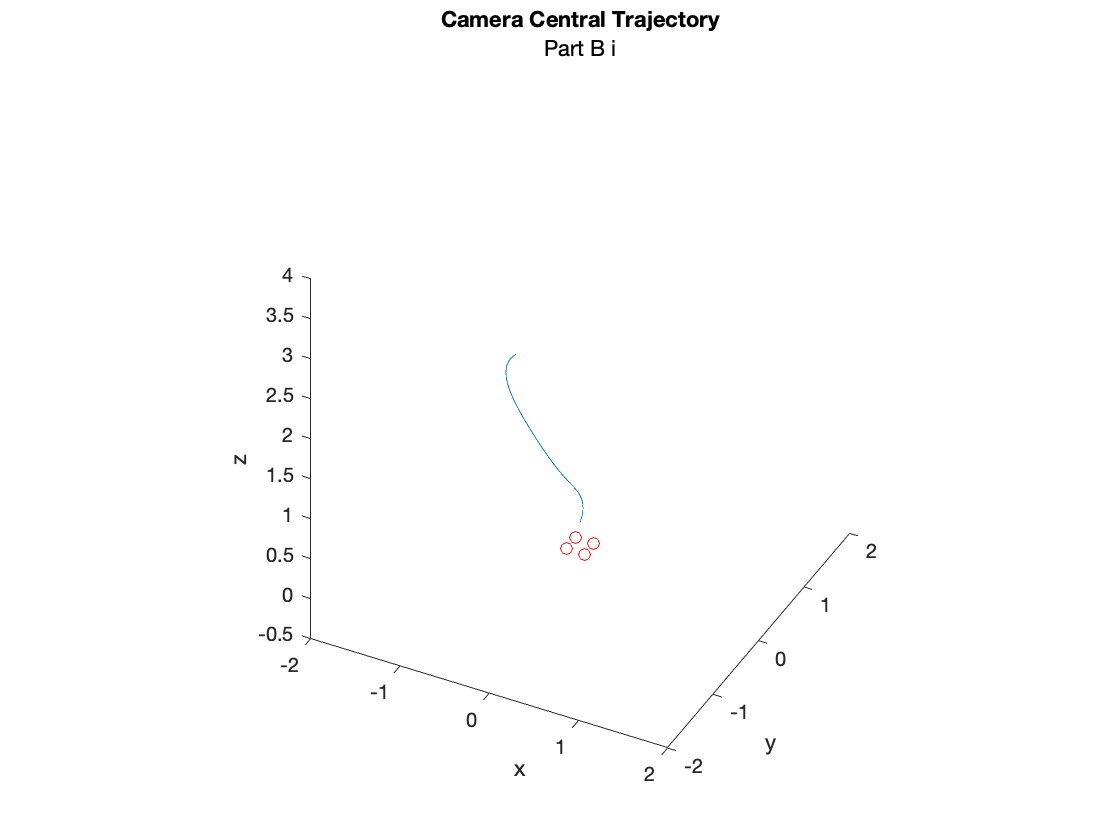

    ccplot(data2, featurePositions,section) 

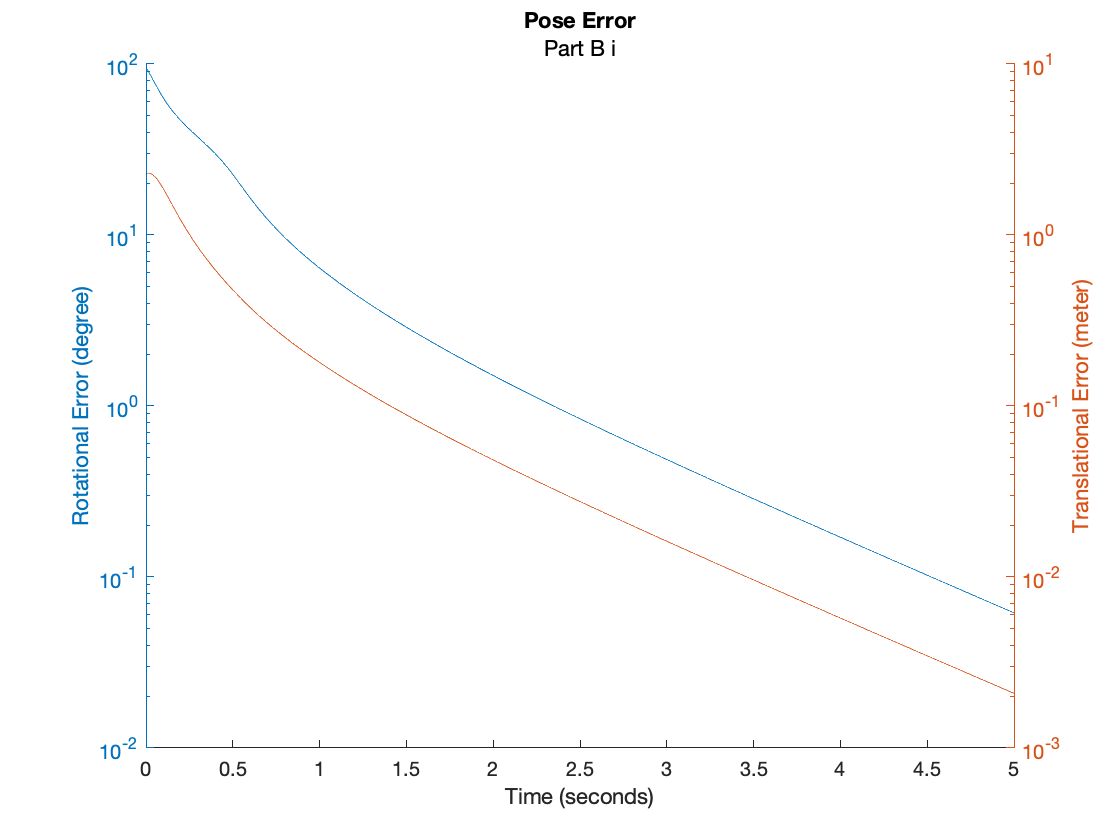

    peplot(N_steps, data2, goal_camera2board_pose, section)

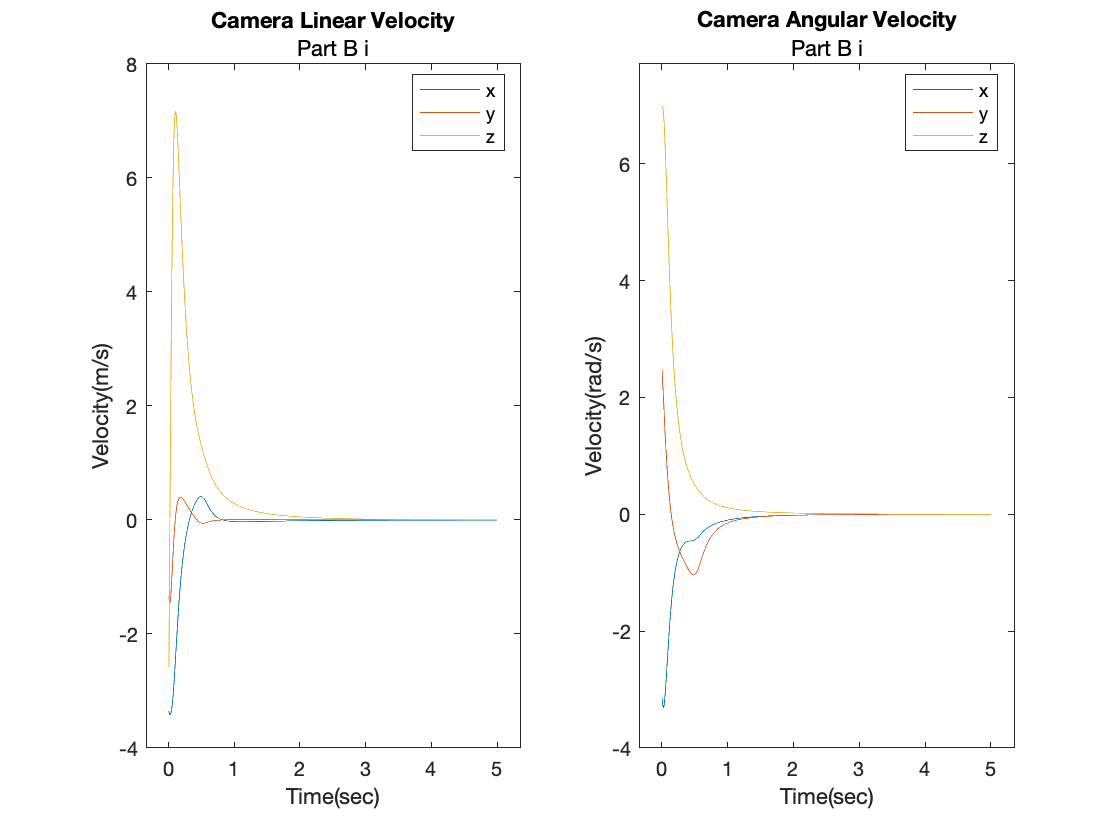

    velplot(N_steps, data2, section)

ii. The true feature depth information is unknown in practice. Instead, we could use a constant feature depth obtained assuming the camera is at the goal position and orientation. Implement the IBVS algorithm with this fixed Z value that can be obtained from the relative pose of the camera with respect to the board (goal_camera2board_pose in the starter code). Run the code. Observe the image plane trajectory, camera center trajectory and pose error plots. Compare the pose error with that obtained in (b)-i. State your observation and analysis. 						

% Part B ii
    section = 'Part B ii'

section = 'Part B ii'

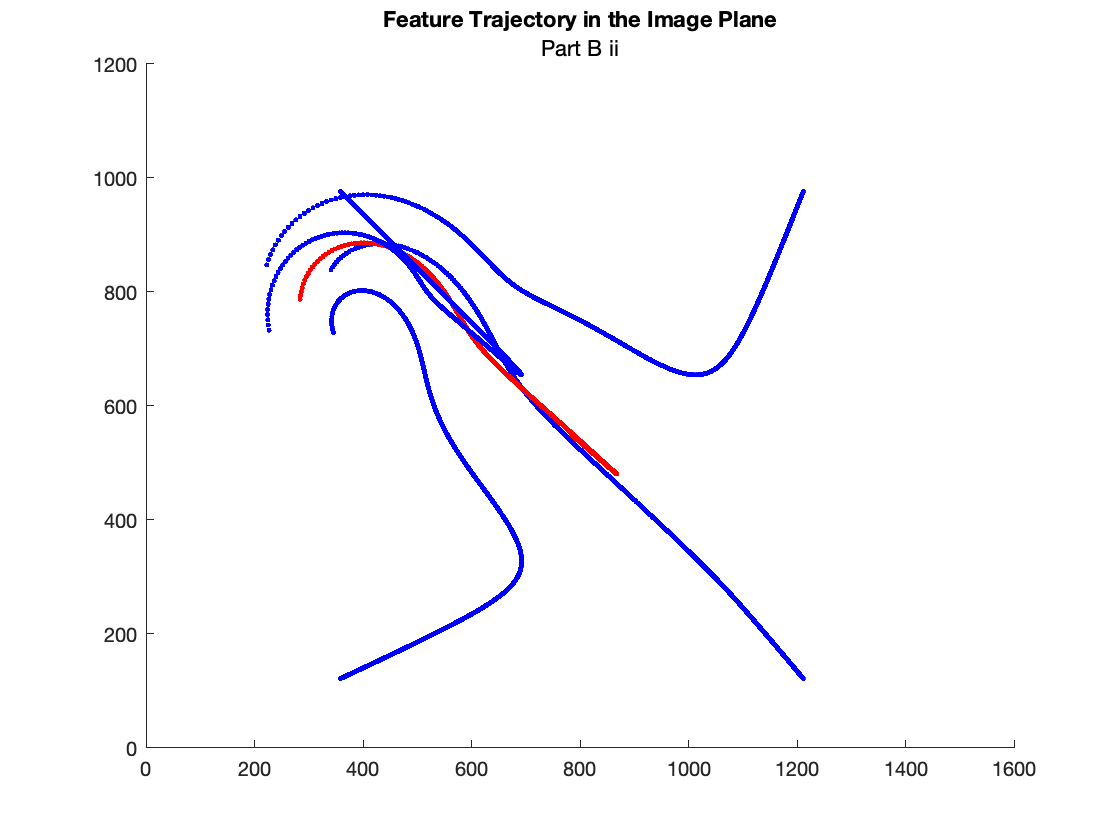

    imgplot(data3, section)

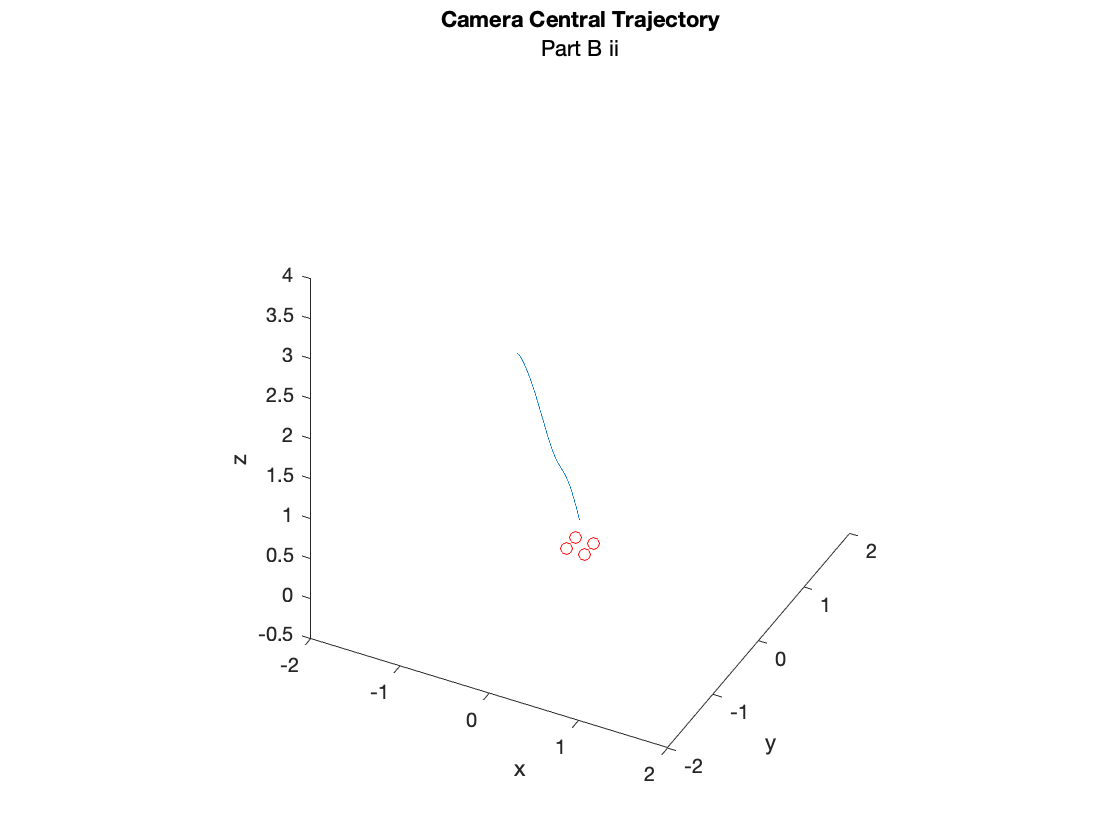

    ccplot(data3, featurePositions,section)

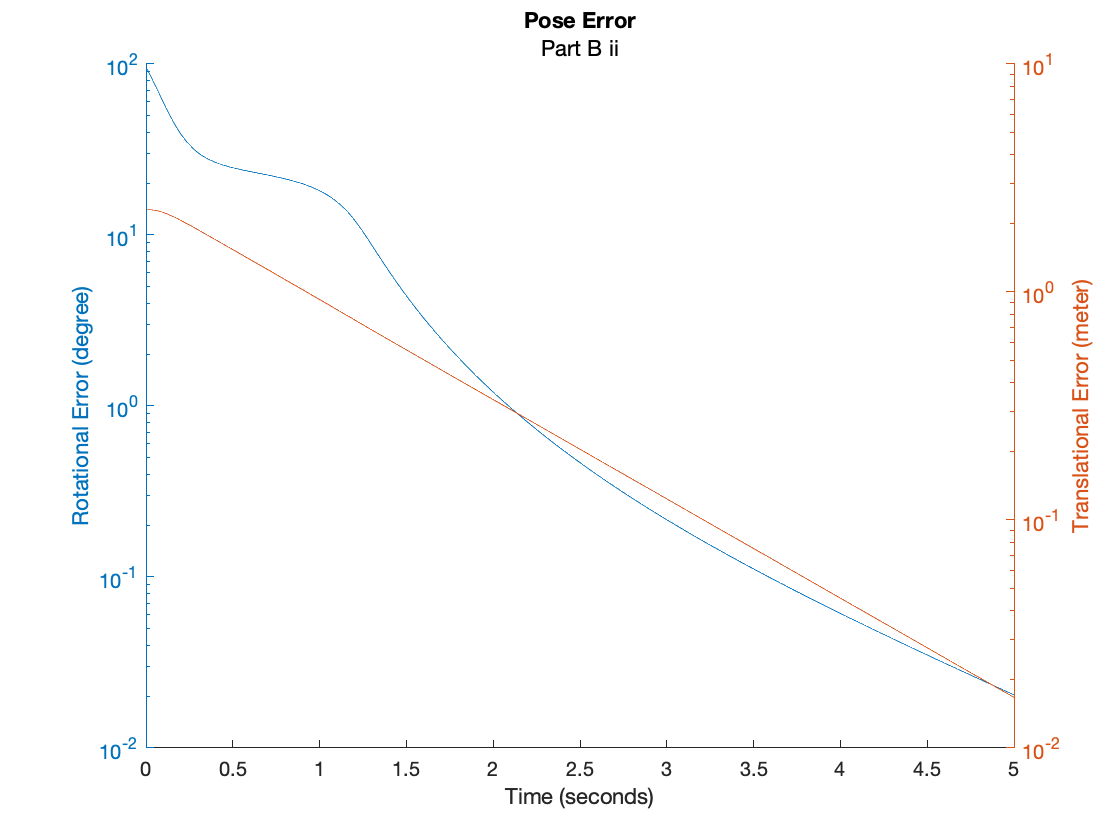

    peplot(N_steps, data3, goal_camera2board_pose, section)

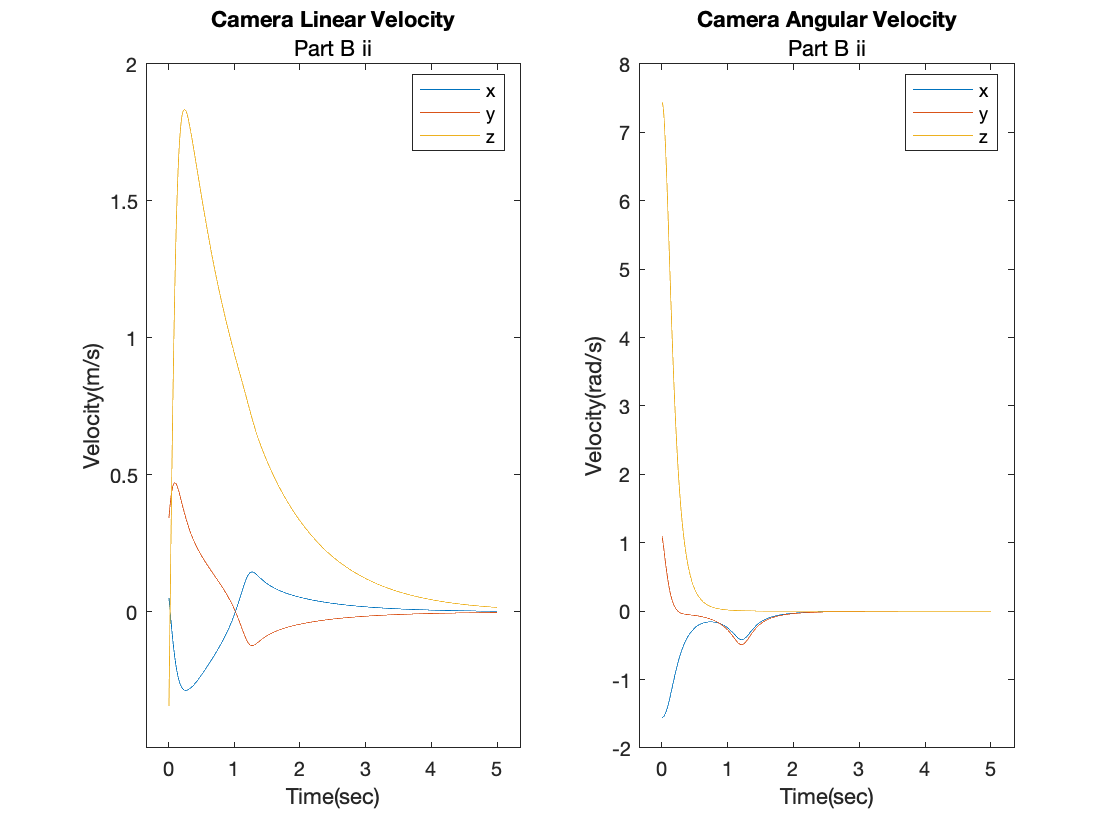

    velplot(N_steps, data3, section)

iii. [sensitivity analysis] Let the fixed Z value in part (b)-ii be Zo. Change the fixed Z value in IBVS to 1.1Zo, 1.3Zo, 1.5Zo, and 2Zo, respectively. Run the code. Observe the image plane trajectory, camera center trajectory and pose error plots. Compare the pose error with that obtained in (b)-i. State your observation and analysis. What about the case if you decrease the implemented Z value in IBVS? 						

% Part B iii
    % Zo = 1.1
    section = 'Zo = 1.1'

section = 'Zo = 1.1'

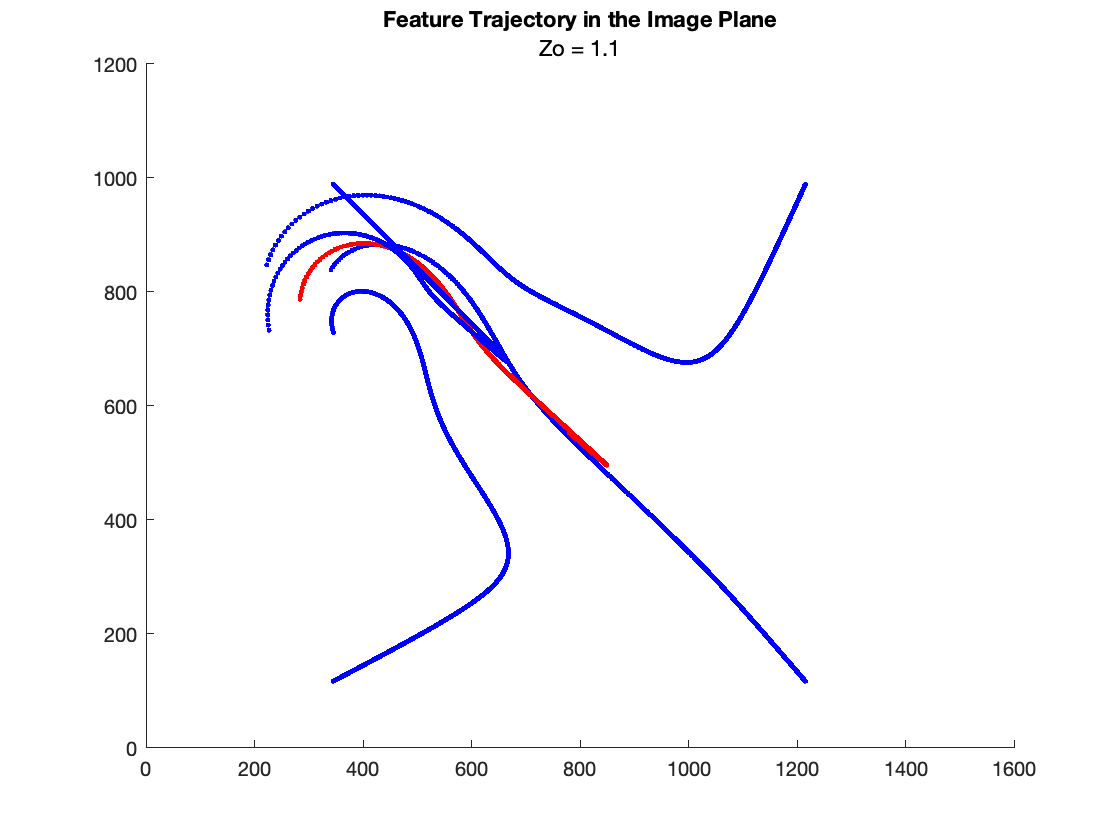

    imgplot(data4, section)

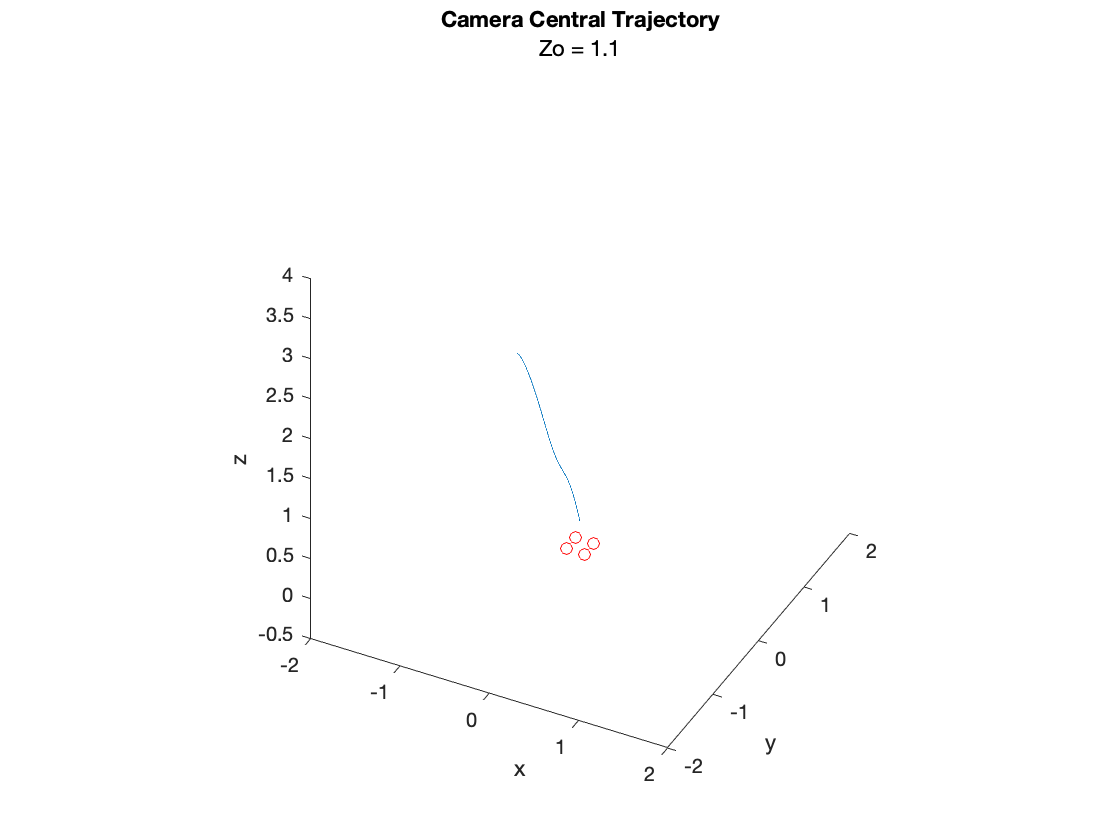

    ccplot(data4, featurePositions,section) 

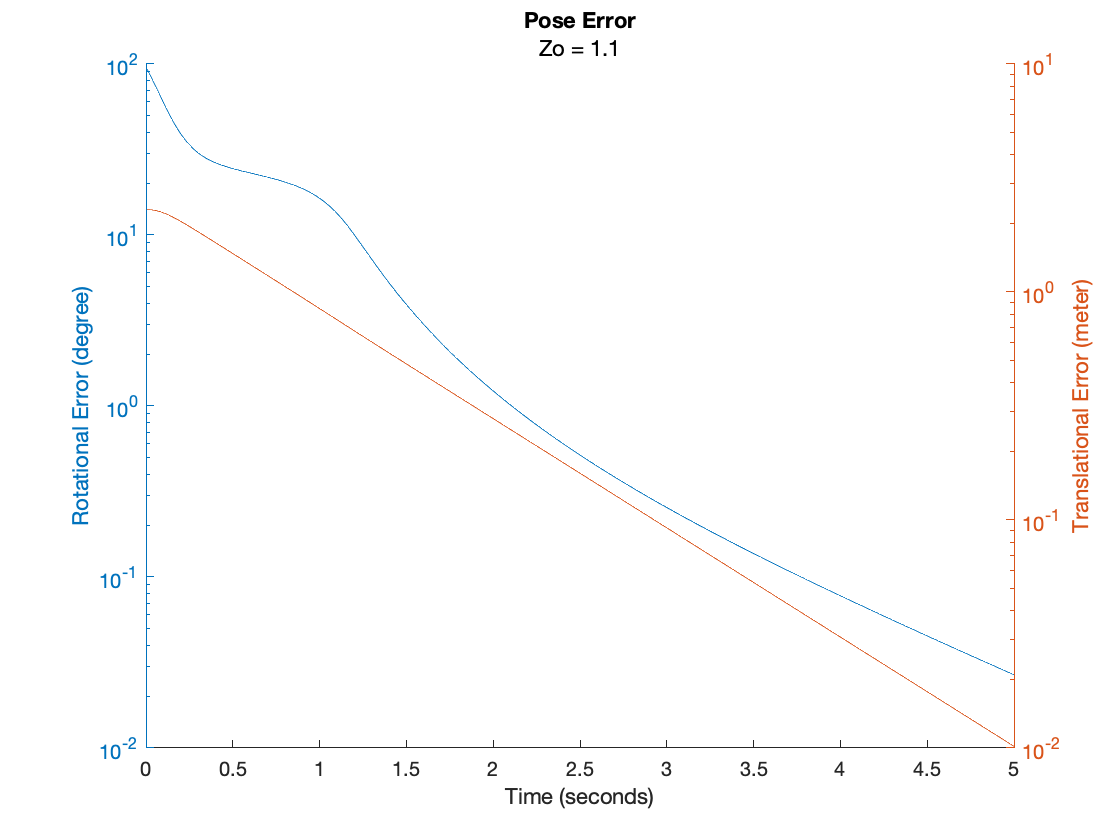

    peplot(N_steps, data4, goal_camera2board_pose, section) 

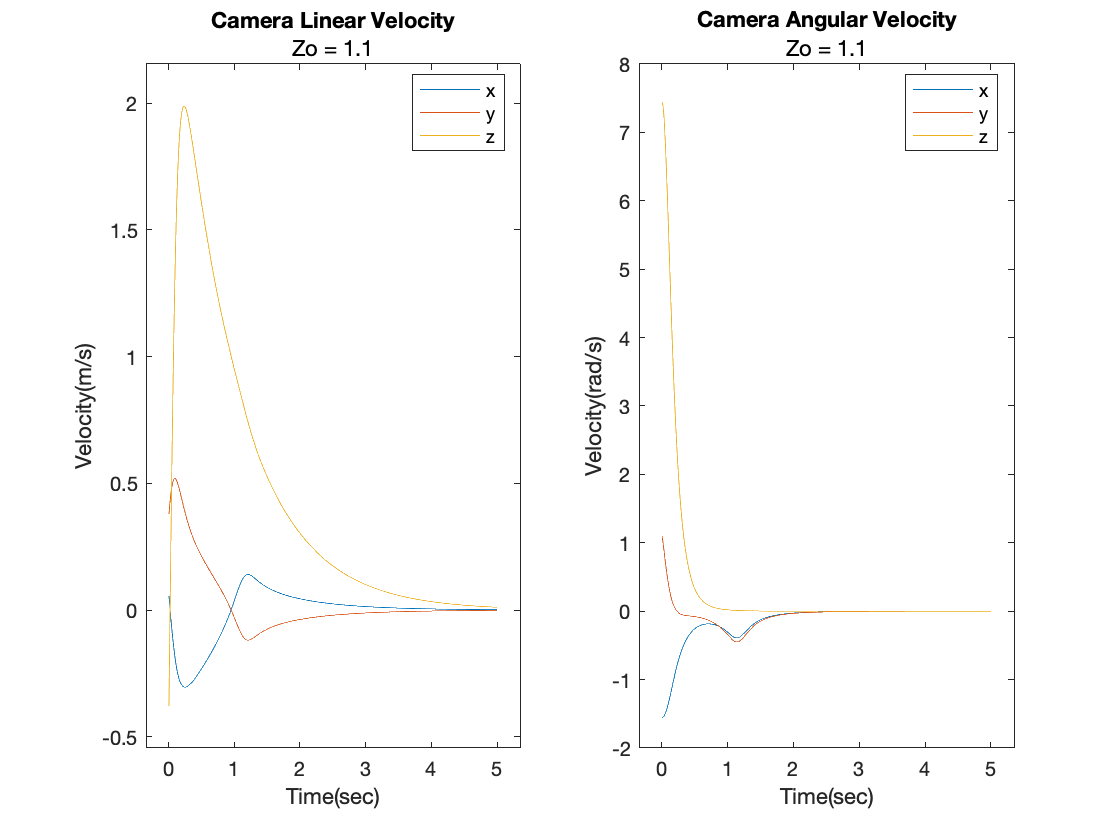

    velplot(N_steps, data4, section)

    
    % Zo = 1.3
    section = 'Zo = 1.3'

section = 'Zo = 1.3'

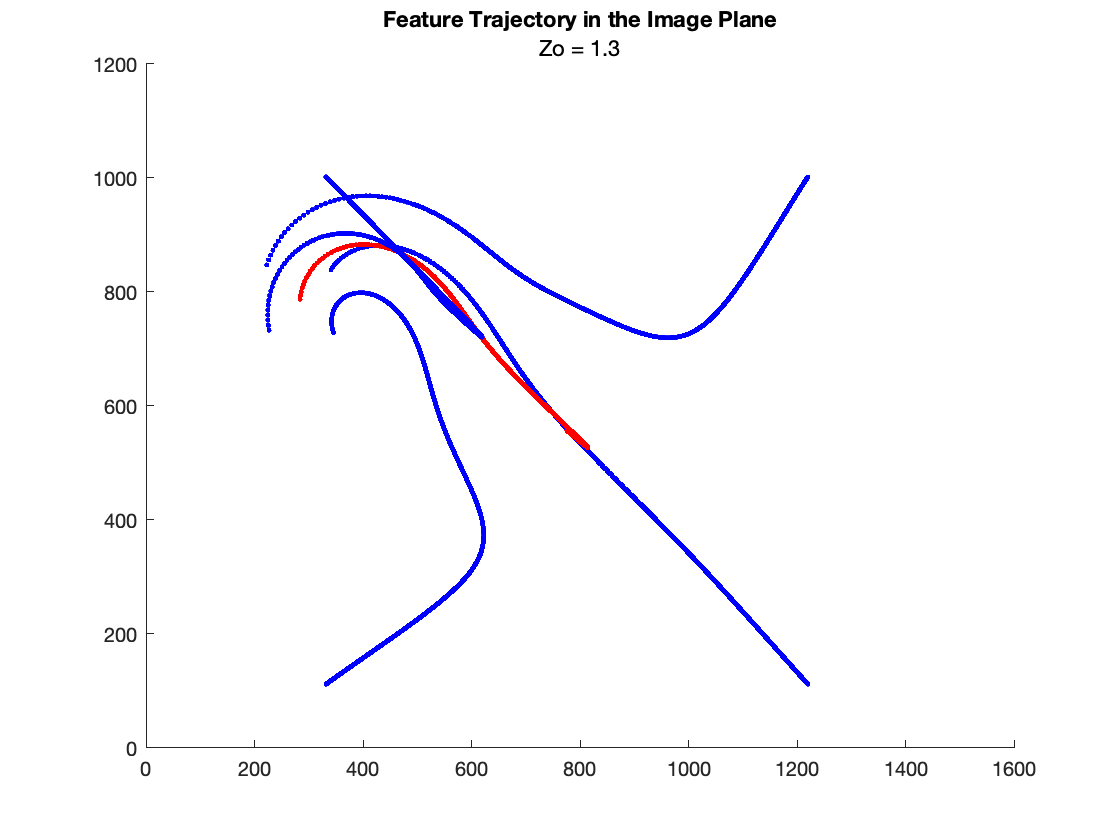

    imgplot(data5, section)

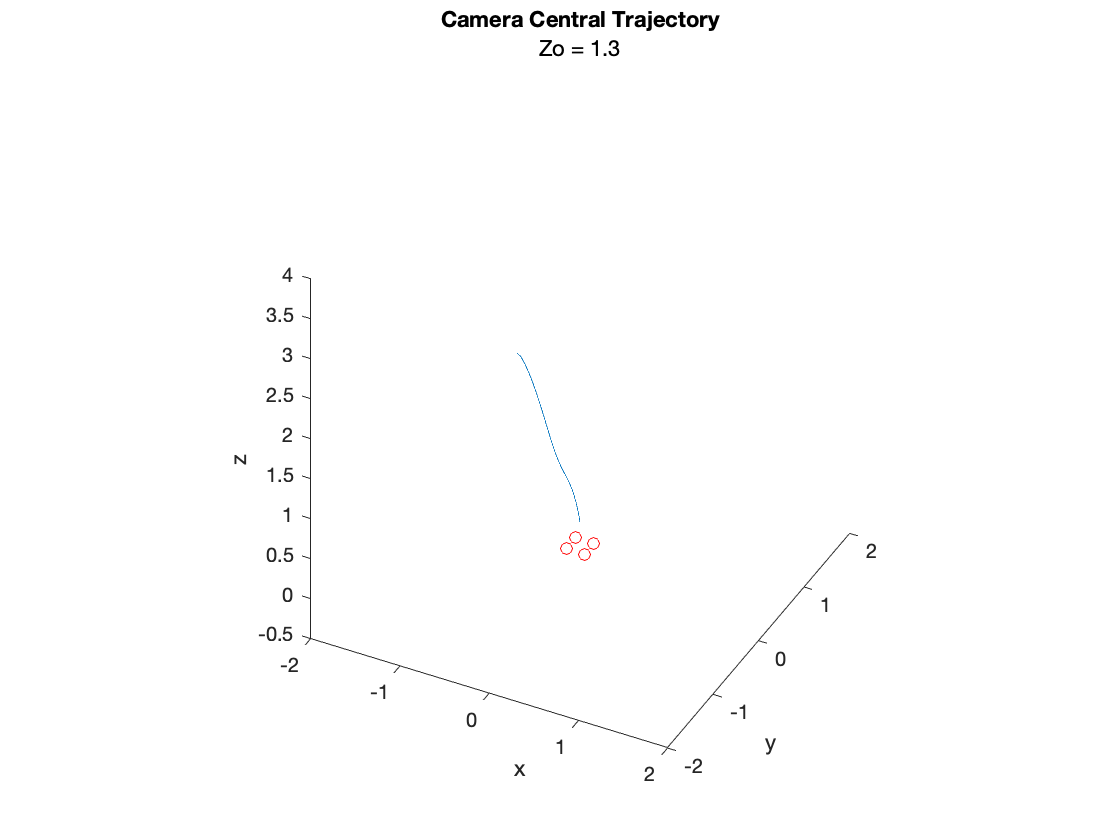

    ccplot(data5, featurePositions,section) 

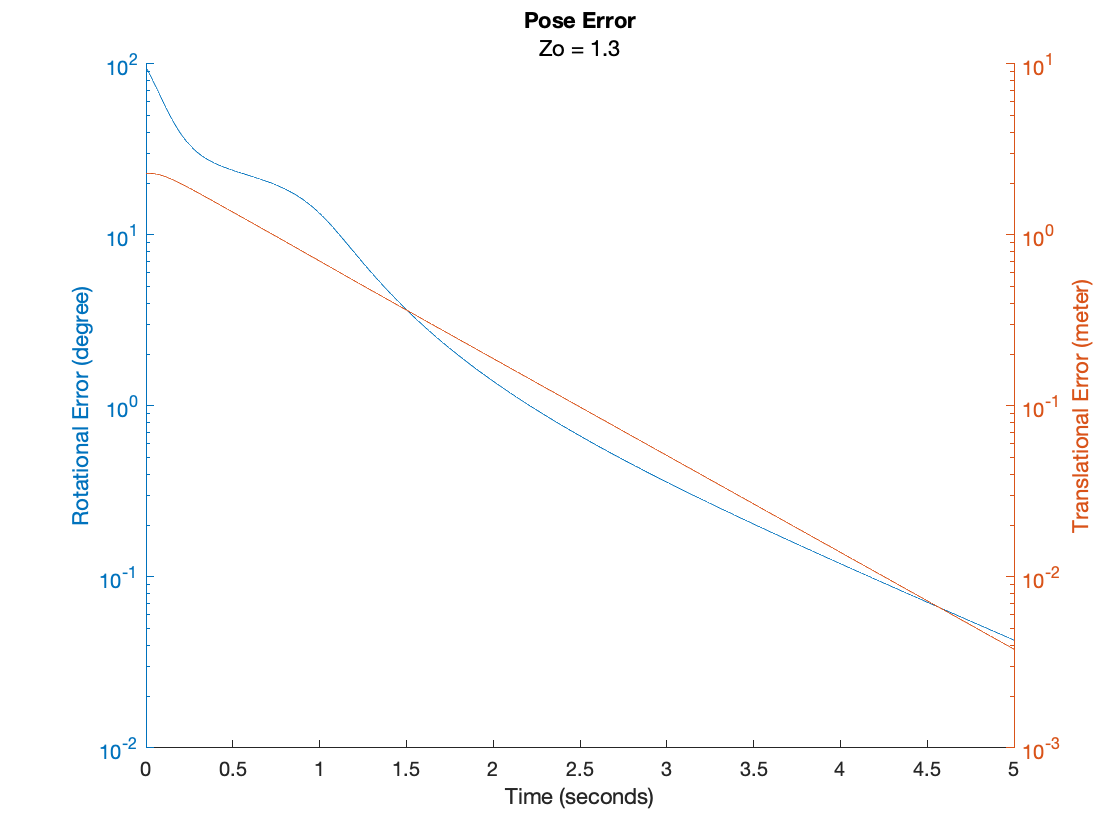

    peplot(N_steps, data5, goal_camera2board_pose, section) 

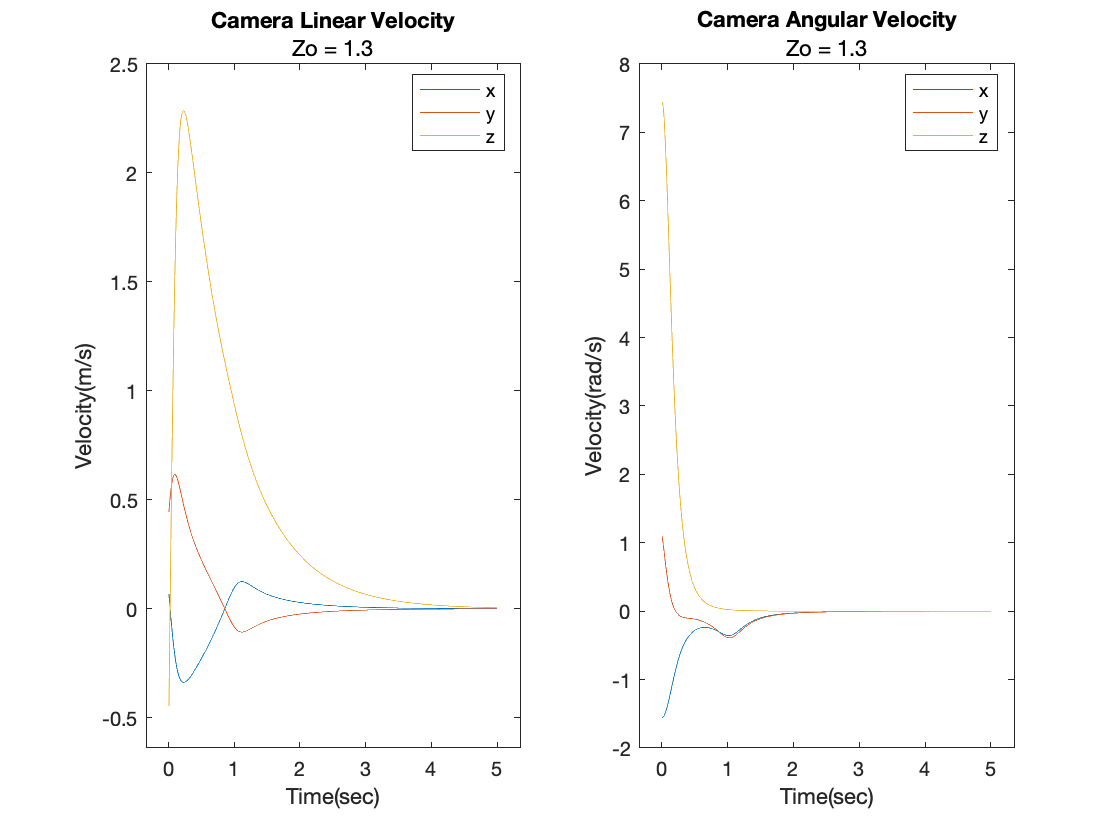

    velplot(N_steps, data5, section) 

    
    % Zo = 1.5
    section = 'Zo = 1.5'

section = 'Zo = 1.5'

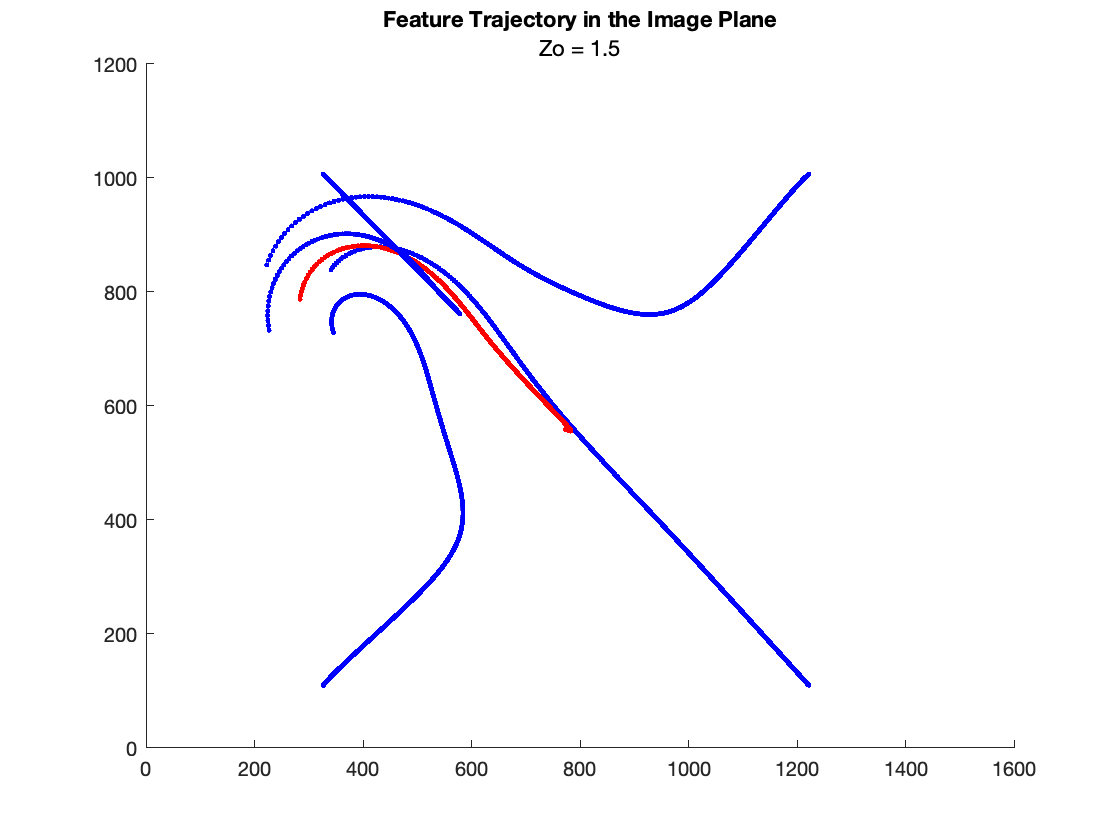

    imgplot(data6, section)

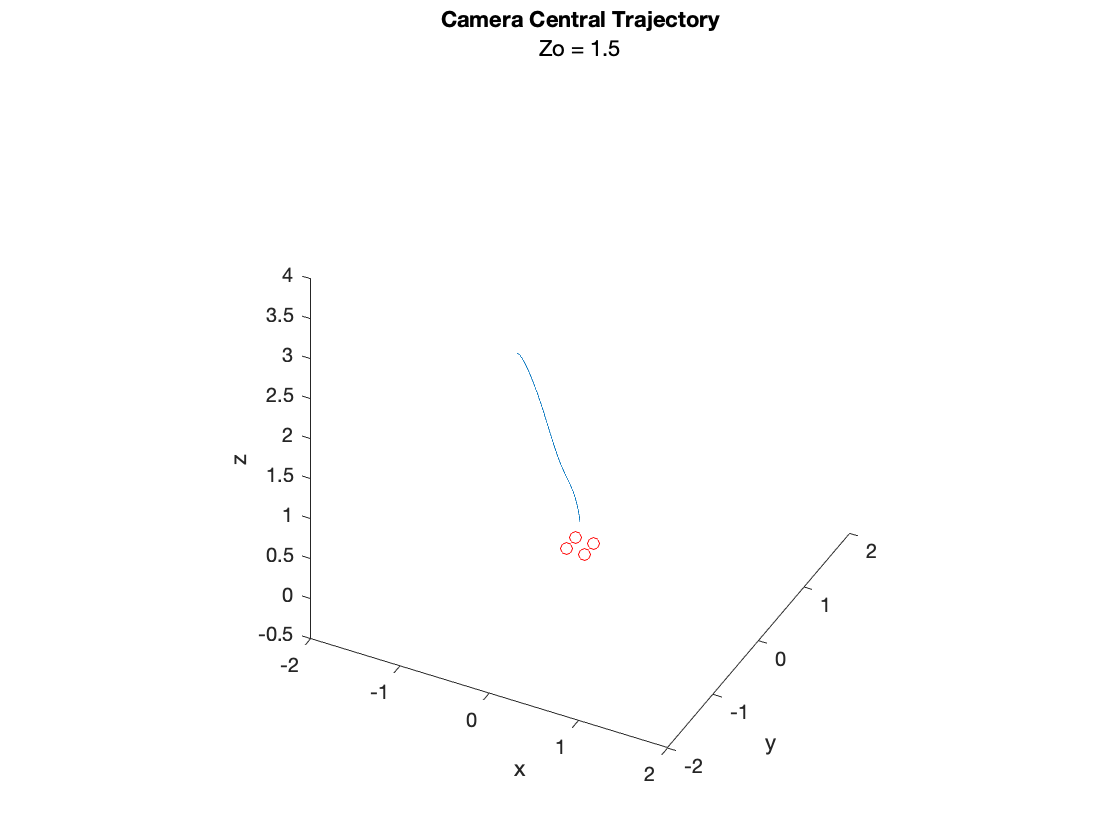

    ccplot(data6, featurePositions,section) 

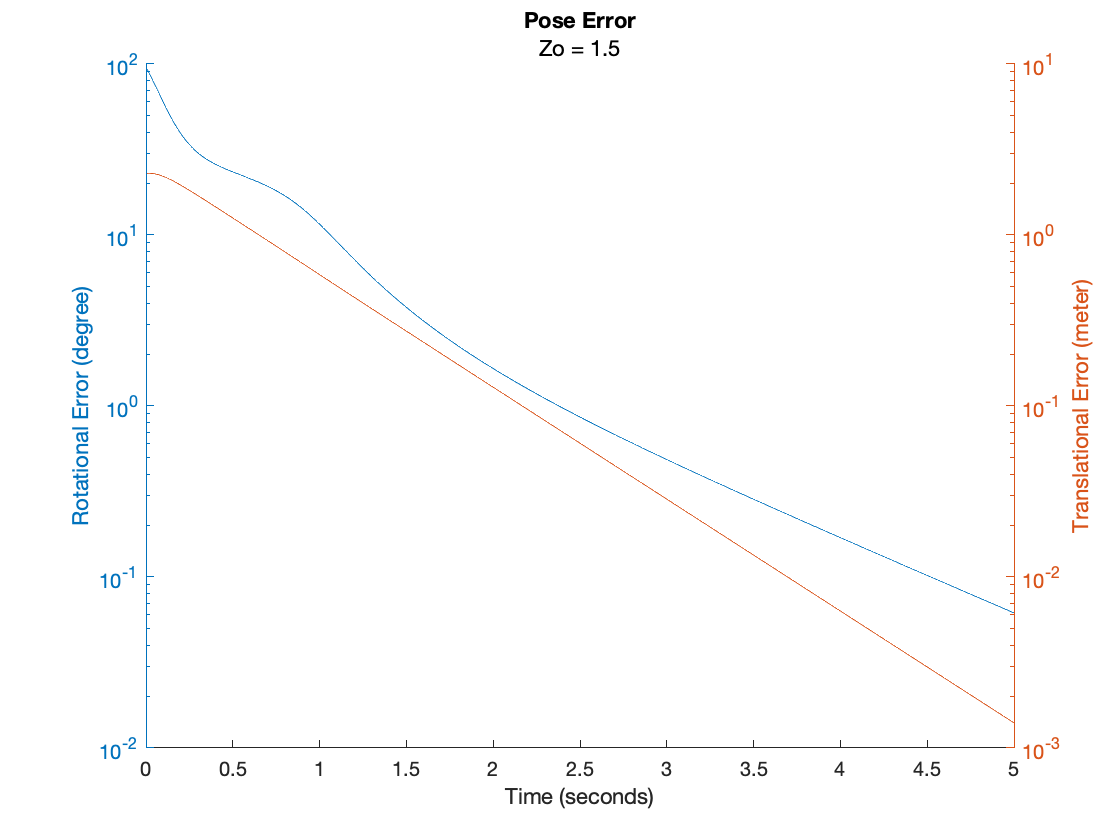

    peplot(N_steps, data6, goal_camera2board_pose, section) 

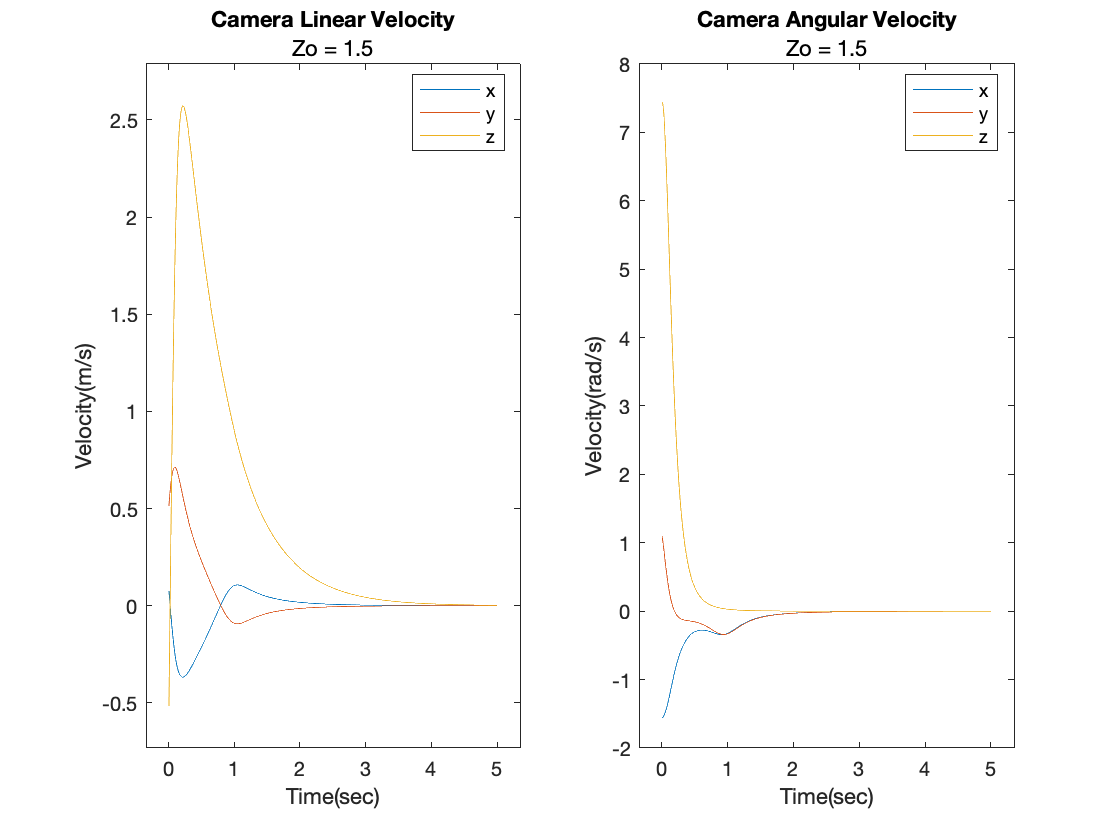

    velplot(N_steps, data6, section)

    
    % Zo = 2
    section = 'Zo = 2'

section = 'Zo = 2'

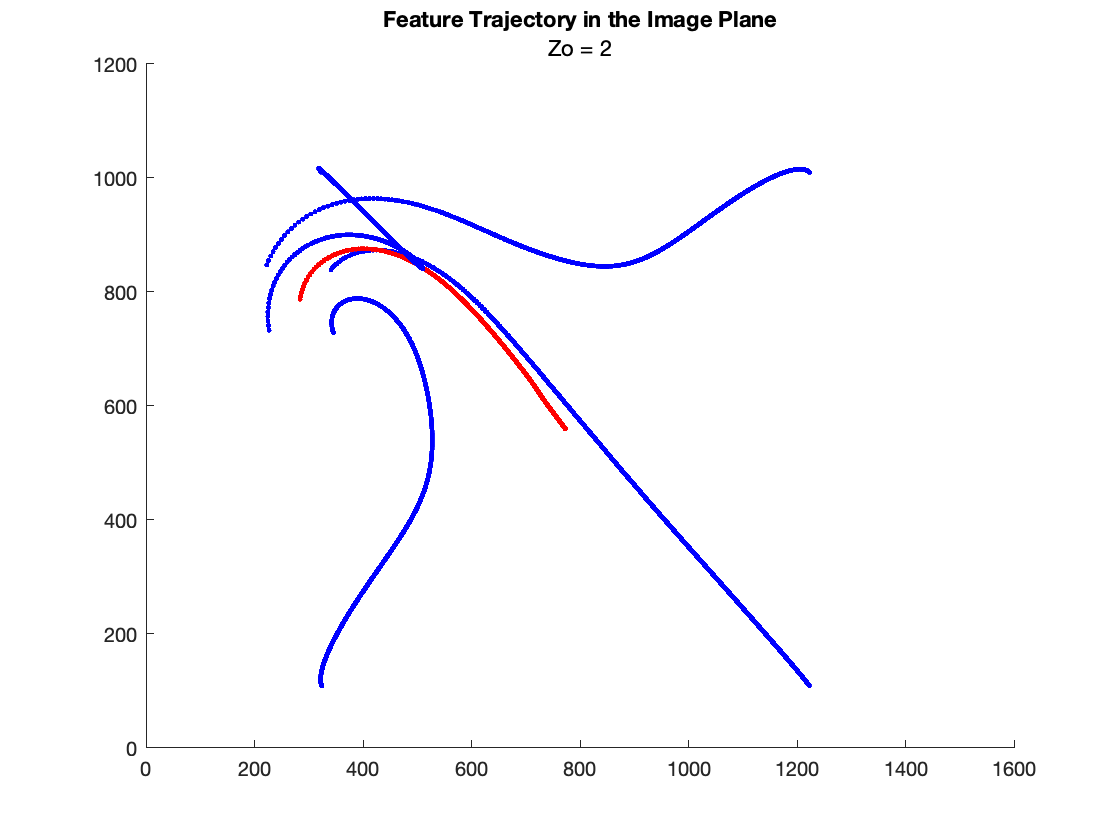

    imgplot(data7, section)

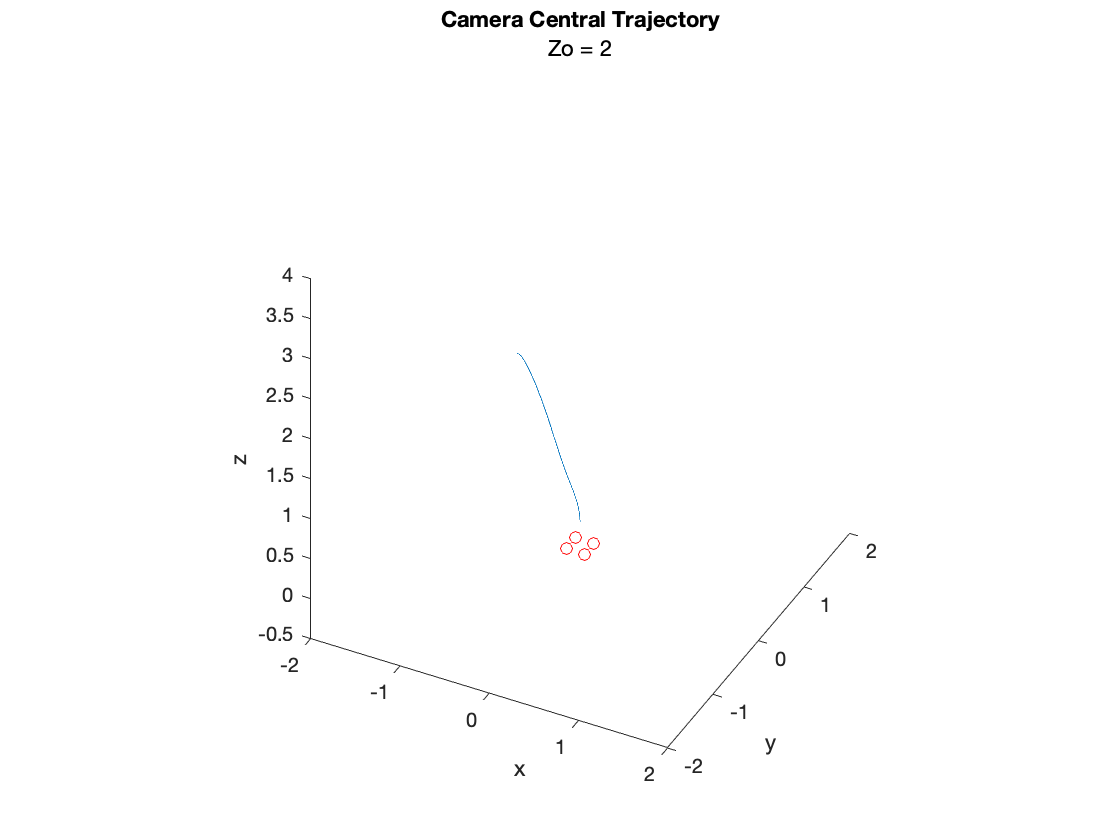

    ccplot(data7, featurePositions,section) 

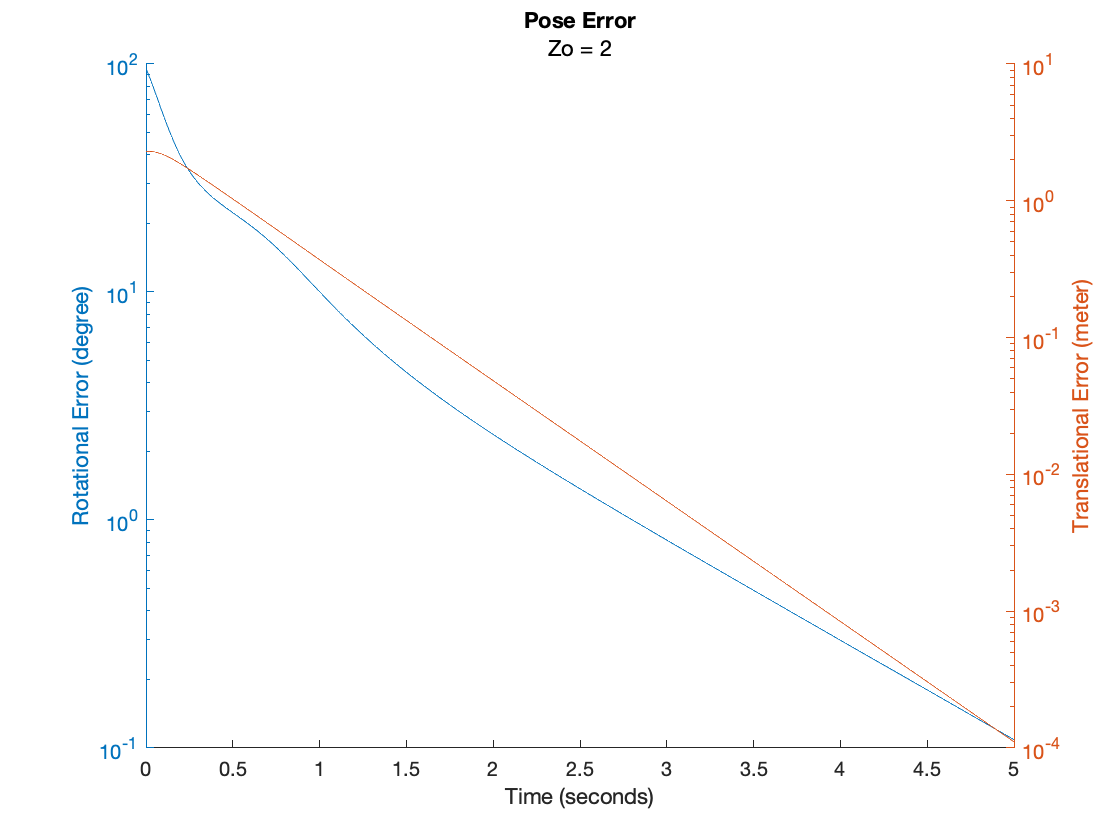

    peplot(N_steps, data7, goal_camera2board_pose, section) 

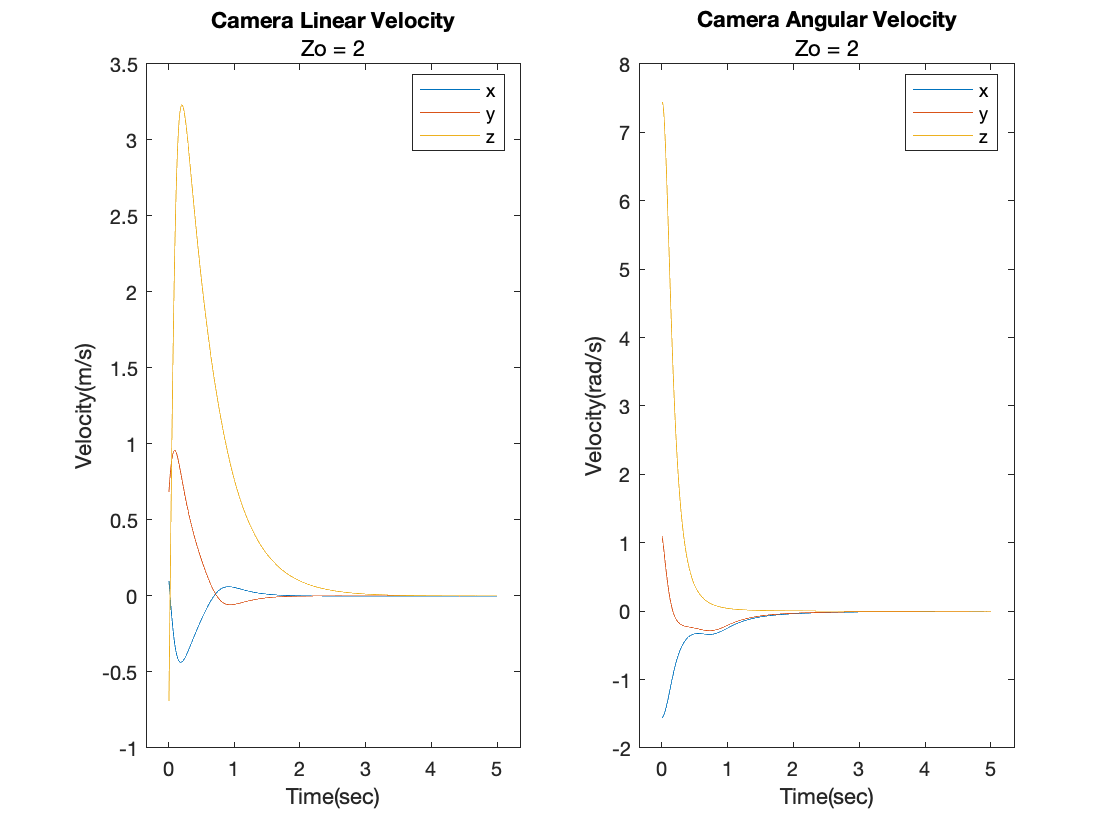

    velplot(N_steps, data7, section) 

(c)  In the provided starting code, the image coordinates of projected feature points are given by simulation. In practice, computer vision algorithm is required to obtain such data. Add a Gaussian noise (μ = 0, σ = 5) to each pixel measurement and run (a) and (b)-i again (use the command imgPoints = imgPoints + normrnd(0, 5, size(imgPoints))). Compare the camera velocity plot with and without noise. Between the methods in (a) and (b)-i, which method do you think will work better when the feature point measurements are noisy? Why? 						

% Part C
    % PBVS
    section = 'PBVS'

section = 'PBVS'

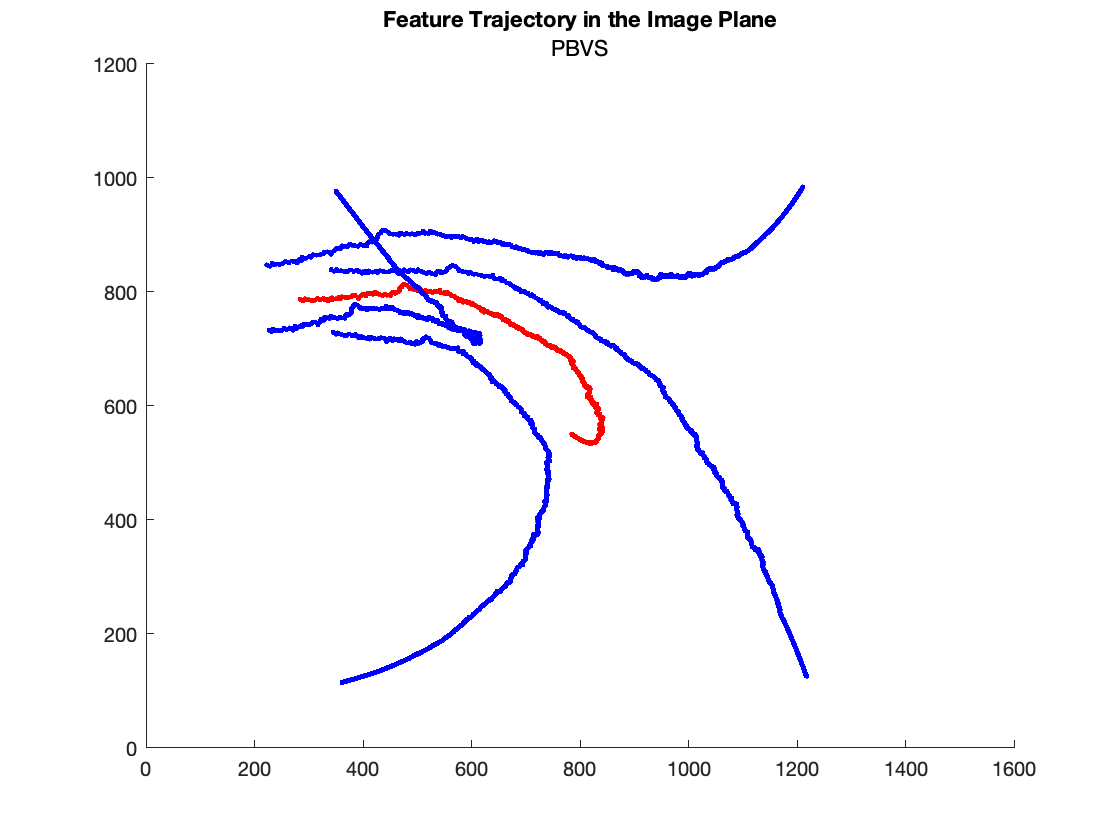

    imgplot(data8, section)

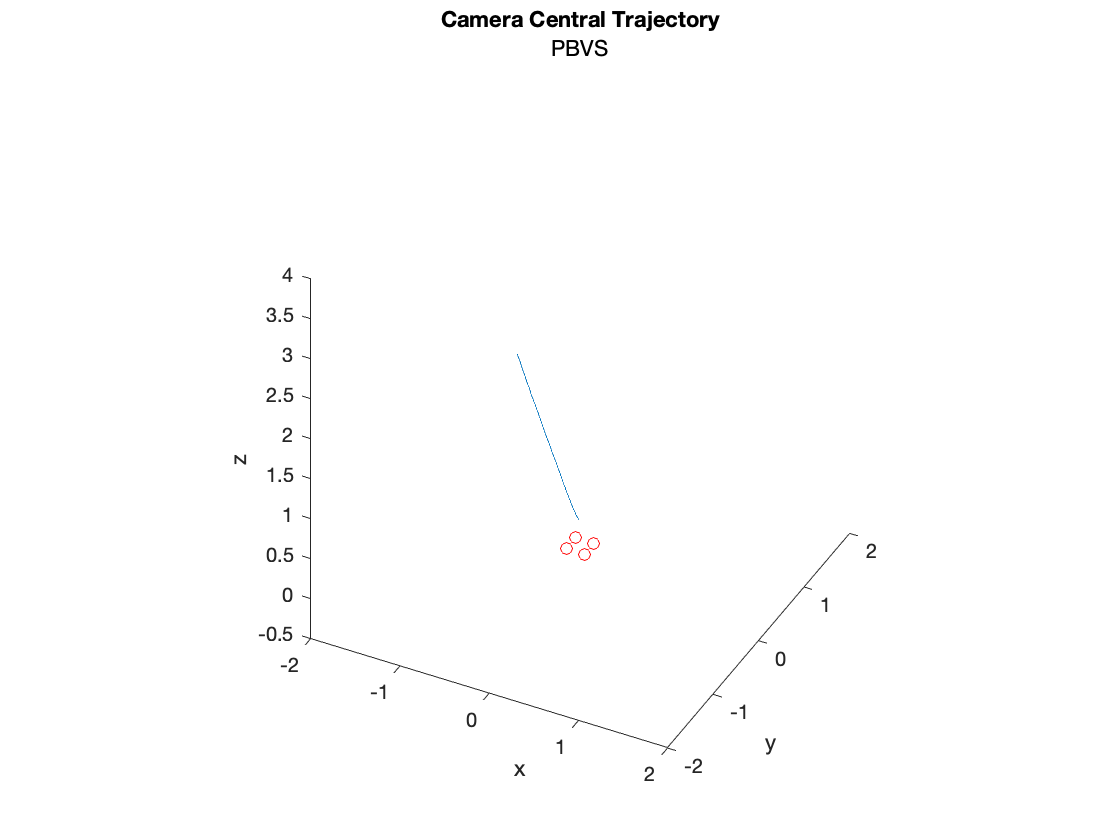

    ccplot(data8, featurePositions,section) 

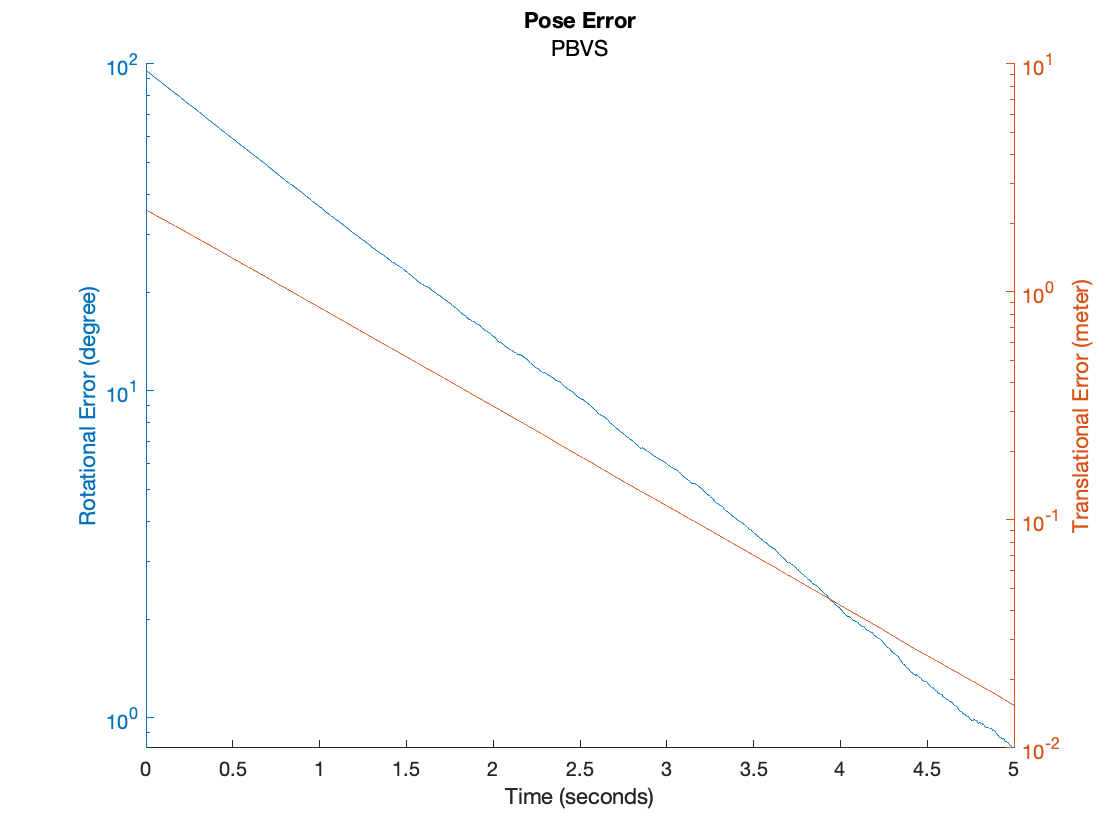

    peplot(N_steps, data8, goal_camera2board_pose, section) 

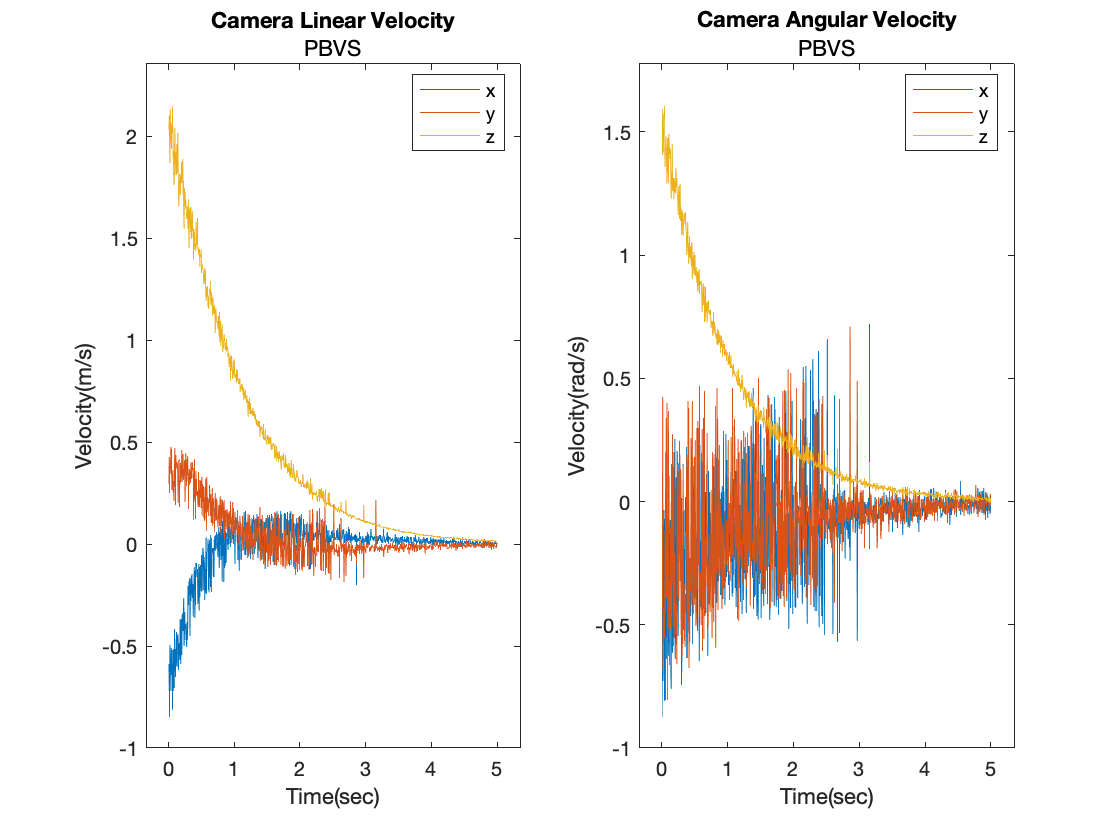

    velplot(N_steps, data8, section) 

    
    % IBVS
    section = 'IBVS'

section = 'IBVS'

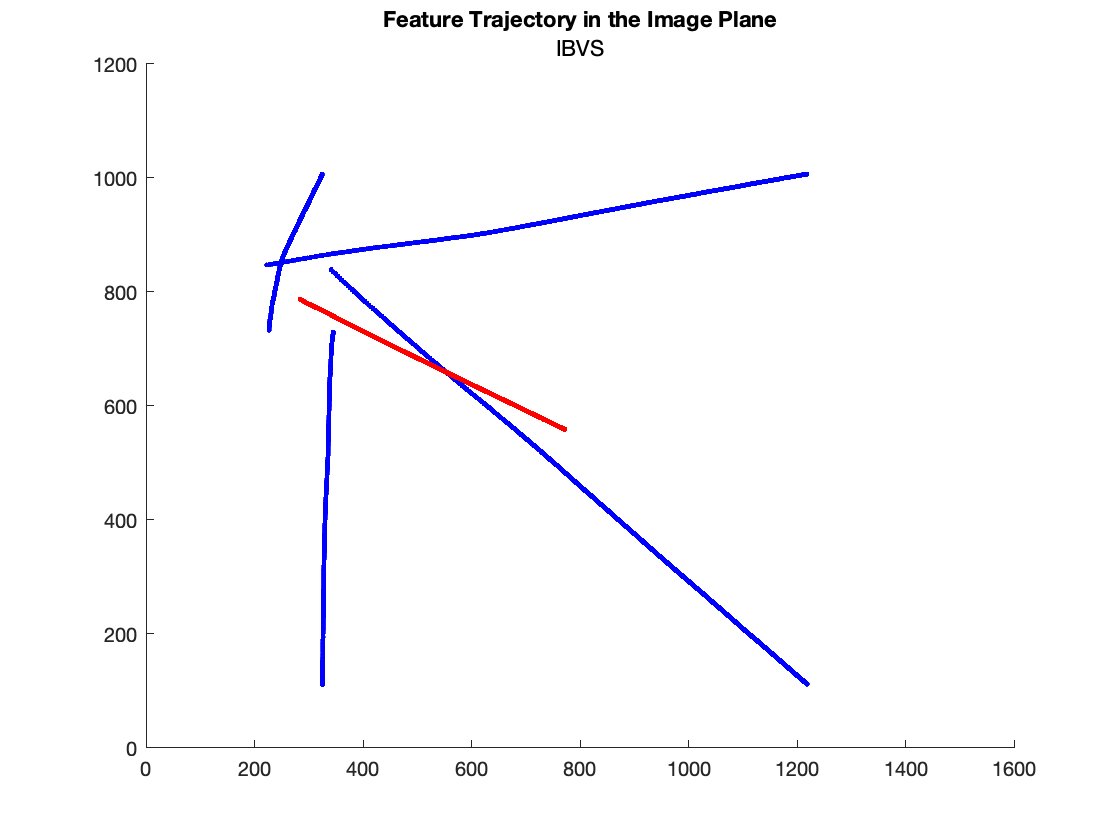

    imgplot(data9, section)

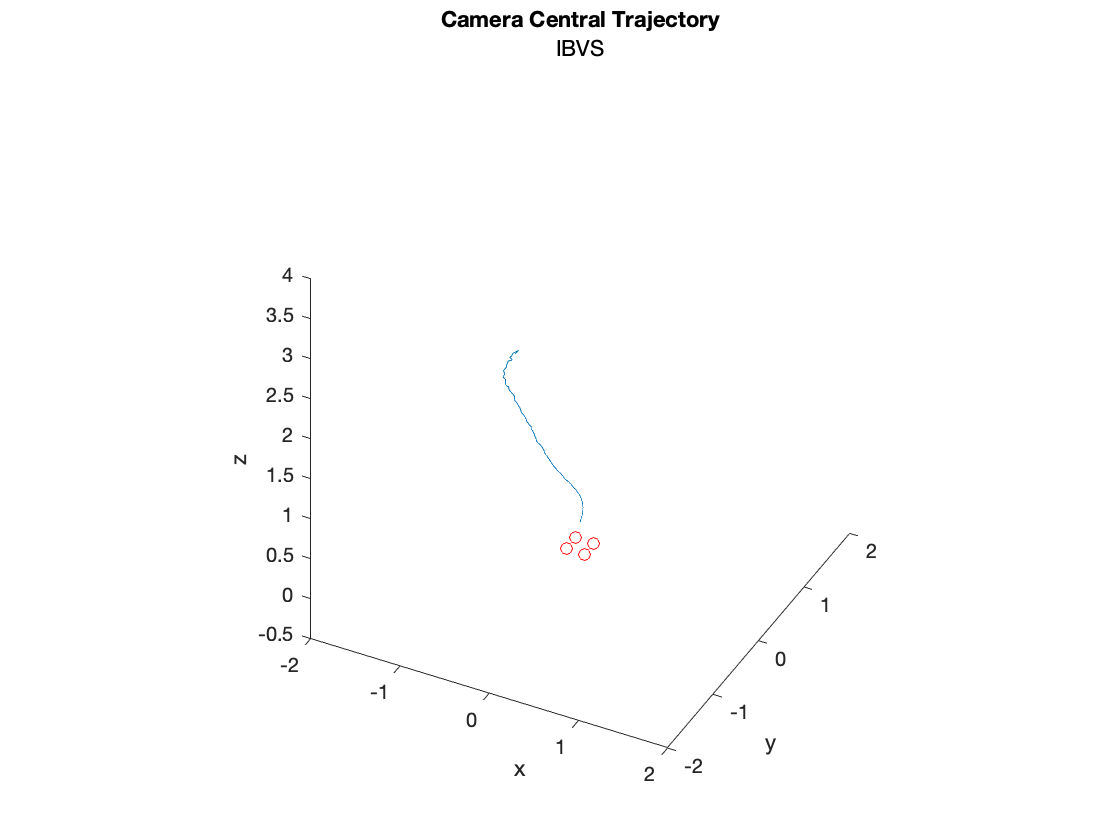

    ccplot(data9, featurePositions,section) 

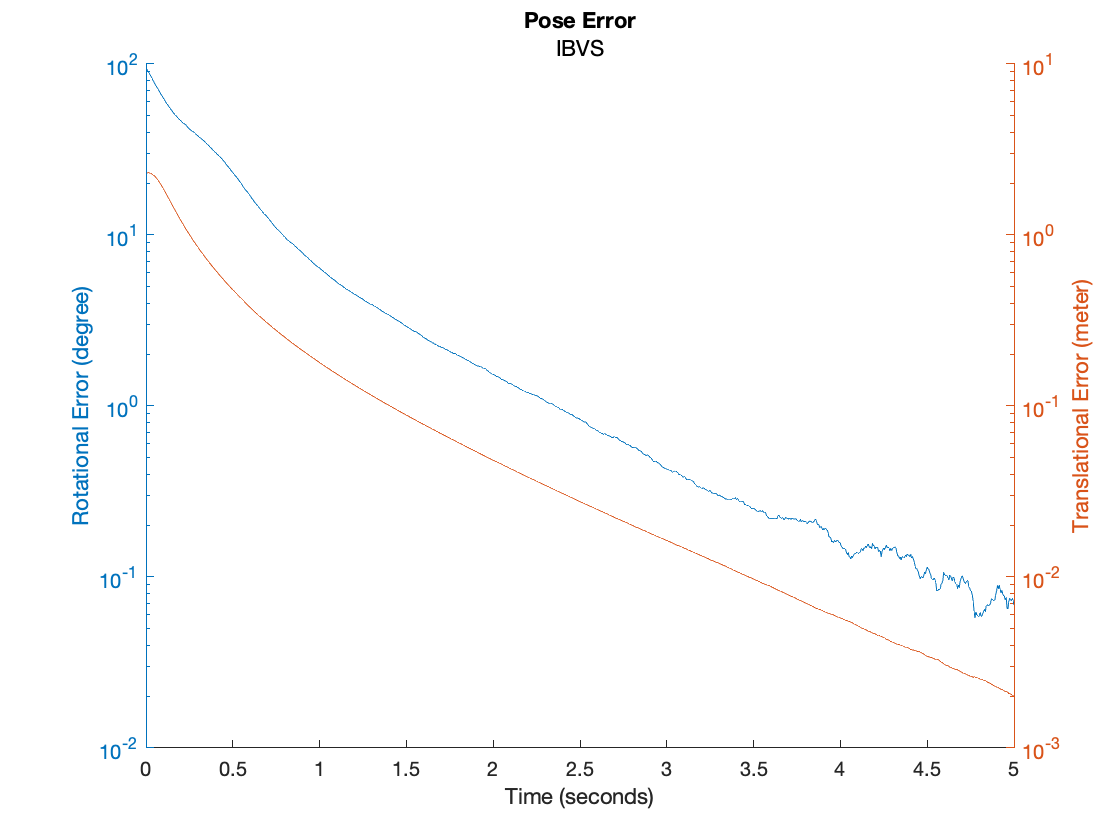

    peplot(N_steps, data9, goal_camera2board_pose, section) 

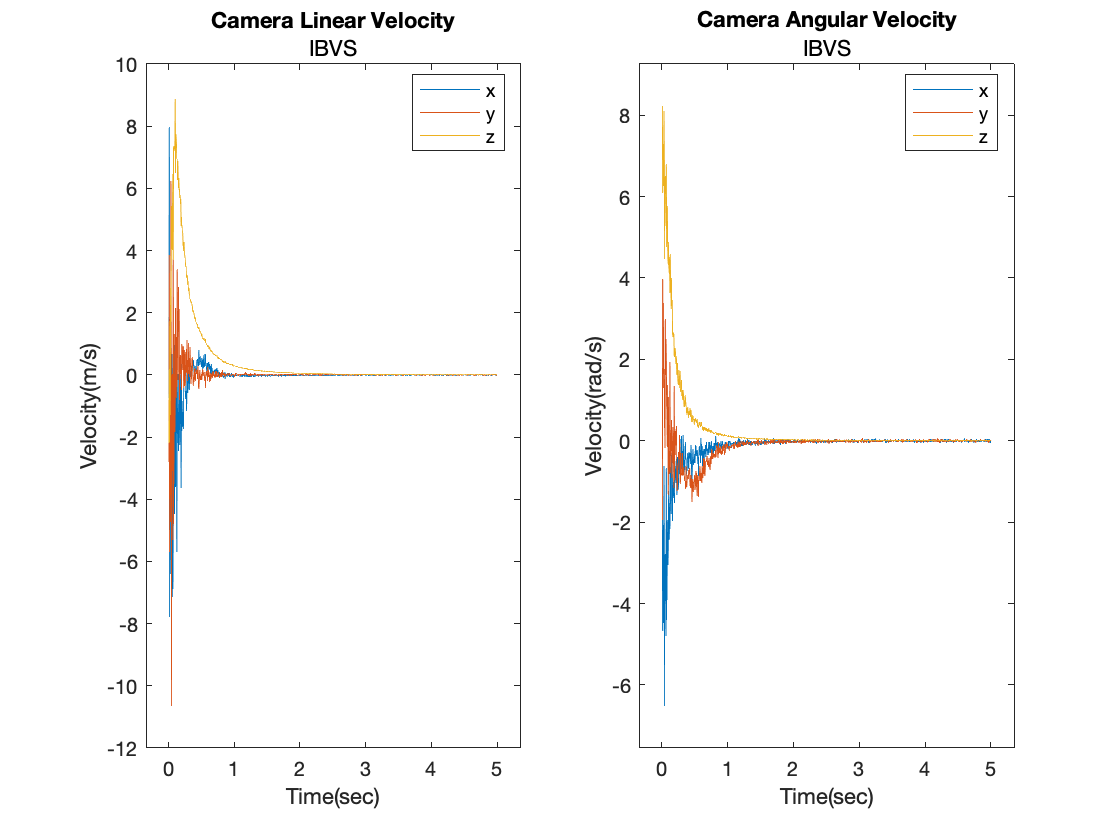

    velplot(N_steps, data9, section) 

%% helper function
% Feel free to construct helper functions and put them here.

function cam_vel = IBVS_step(imgPoints, camera, featurePositions,...
                        goal_camera2board_pose,state_obj,lambda,TD,n,camera_param)
% New varible defintions
    %feature positions = world coordinate board location
    %goal_camera2board_poser = desired pose
    %lambda = gain
    %TD = depth defintion, 0 = [Z = 0.3 (fixed)], 1 = [Z = true depth]
    %n = Z multiplication factor

% Determine True or Fixed Depth
    if TD == 1
        Z = state_obj.getFeatureDepth(); % True Depth
    else
        Z = n*ones(4)*0.3; % Fixed Depth
    end


% find cam_vel = lambda*inv(Jp'*Jp)*Jp'*(ps-p)
% pseudo-inverse for Jp = inv(Jp.T*Jp)*Jp.T
% finding desired position

% cameraProjection = (K, final rotation of the pose, final translation of
% the pose, world coordinates of the board)

% Ps finds the desired locations of the pixels on the 2D image
Ps = cameraProjection(camera.K,goal_camera2board_pose(1:3,1:3),...
    goal_camera2board_pose(1:3,4),featurePositions);

% P_t = Ps (desired) - imgPoints (actual location), E(error)
    P_t = Ps-imgPoints;

% P_ puts P_t as a 8x1 column vector [u1;v1;u2,v2;...u4;v4]
    P_ = [P_t(1,1);P_t(2,1);... 
    P_t(1,2);P_t(2,2);...
    P_t(1,3);P_t(2,3);...
    P_t(1,4);P_t(2,4)];
    J = visjac_p(camera_param, imgPoints, Z);
    cam_vel = lambda*pinv(J)*P_;
    
end

function cam_vel = PBVS_step(imgPoints, camera, featurePositions,...
                        goal_camera2board_pose, lambda, method)
    % pose estimation
    camera_param = cameraIntrinsics([camera.K(1,1), camera.K(2,2)],...
                                    [camera.K(1,3), camera.K(2,3)], ...
                                     camera.img_size);
    [board2camera_R, board2camera_t] = estimateWorldCameraPose(imgPoints',...
                                         featurePositions', camera_param,...
                                         'Confidence', 99.99,...
                                         'MaxReprojectionError', 1000);
    camera2board_pose = [board2camera_R, -board2camera_R*board2camera_t'; ...
                         0 0 0 1];
    % pbvs
    cam_vel = lambda * pbvs(camera2board_pose, goal_camera2board_pose, method);
end

function command_vel = pbvs(c2t, desired_c2t, method)
    % c2t is the pose from camera to target object
    % desired_c2t is the desired pose from camera to target object

    cstar2c = desired_c2t/c2t;
    R = cstar2c(1:3,1:3);   % rotation matrix
    t = cstar2c(1:3,4);     % translation matrix
    t_c2t = c2t(1:3,4);
    t_desired_c2t = desired_c2t(1:3,4);
    axang = rotm2axang(R);
    v = axang(1:3)';
    theta = axang(4);
    if method == 1
        v_c = -R'*t;
        omega_c = -theta*v;
    else
        % code here for other velocity control laws
    end

    command_vel = [v_c;omega_c];

        function S = skew(V)
            S = [0, -V(3), V(2); V(3), 0, -V(1); -V(2), V(1) 0];
        end
end

function J = visjac_p(camera_param, uv, Z)

    u0 = camera_param.PrincipalPoint(1); % prinicipal points
    v0 = camera_param.PrincipalPoint(2); % prinicipal points
    f_dividedby_rhou = camera_param.FocalLength(1);
    f_dividedby_rhov = camera_param.FocalLength(2);
    if numcols(uv) > 1
        J = [];
        if length(Z) == 1
            % if depth is a scalar, assume same for all points
            Z = repmat(Z, 1, numcols(uv));
        end
        % recurse for each point
        for i=1:numcols(uv)
            J = [J; visjac_p(camera_param, uv(:,i), Z(i))];
        end
        return;
    end
    
    % convert to normalized image-plane coordinates
    x = (uv(1) - u0) /f_dividedby_rhou;
    y = (uv(2) - v0) /f_dividedby_rhov;

    J = [
        1/Z, 0, -x/Z, -x*y, (1+x^2), -y
        0, 1/Z, -y/Z, -(1+y^2), x*y, x
        ];

    J = -1 * diag(camera_param.FocalLength) * J;
end

function imgplot(data, section)
% Plot image plane trajectory
    figure, hold on
    num_data = size(data,1);    
    for i = 1:num_data
        imgPoints = data{i}.imagePoints;
        plot(imgPoints(1,:),imgPoints(2,:),'.b');
        plot(mean(imgPoints(1,:)), mean(imgPoints(2,:)), '.r');
        % Red line is the trajectory of the feature center.
        axis([0 1600 0 1200]);
    end
    title('Feature Trajectory in the Image Plane',section)
end 

function ccplot(data, featurePositions,section)
% Plot camera center trajectory
    num_data = size(data,1);    

    camera_central.x = zeros(num_data,1);
    camera_central.y = zeros(num_data,1);
    camera_central.z = zeros(num_data,1);
    camera_central.time = zeros(num_data,1);
        
    for i = 1:num_data
        cameraPose = data{i}.cameraPose;
        camera_central.x(i) = cameraPose(1,4);
        camera_central.y(i) = cameraPose(2,4);
        camera_central.z(i) = cameraPose(3,4);
        camera_central.time(i) = data{i}.time;
    end
    
    figure, hold on
    plot3(camera_central.x, camera_central.y, camera_central.z); hold on
    plot3(featurePositions(1,:), featurePositions(2,:), featurePositions(3,:), 'or');
    xlabel('x'); ylabel('y'); zlabel('z');
    axis([-1 1 -1 1 0 4])
    title('Camera Central Trajectory',section);
    view(27,37)
    axis equal
    xlim([-2 2]);
    ylim([-2 2]);
    zlim([-0.5 4])
        
end

function peplot(N_steps, data, goal_camera2board_pose, section)
% plot pose error vs time
    num_data = size(data,1);
    rotation_error = zeros(N_steps, 1);
    translation_error = zeros(N_steps,1);
    time = zeros(N_steps,1);
    
    for i = 1:num_data
        cam_pose = data{i}.cameraPose;
        error_pose = goal_camera2board_pose * cam_pose;
        translation_error(i) = norm(tform2trvec(error_pose));
        angaxis = tform2axang(error_pose);
        rotation_error(i) = abs(angaxis(4));
        time(i) = data{i}.time;
    end
    
    figure, hold on
    title('Pose Error', section);
    yyaxis left
    plot(time, rotation_error*180/pi);
    set(gca, 'YScale', 'log')
    ylabel('Rotational Error (degree)')
    yyaxis right
    plot(time, translation_error);
    set(gca, 'YScale', 'log')
    ylabel('Translational Error (meter)');
    xlabel('Time (seconds)')
end

function velplot(N_steps, data, section)
% plot camera velocity
    cam_velocity.time = zeros(N_steps, 1);
    cam_velocity.l.x = zeros(N_steps, 1);
    cam_velocity.l.y = zeros(N_steps, 1);
    cam_velocity.l.z = zeros(N_steps, 1);
    cam_velocity.a.x = zeros(N_steps, 1);
    cam_velocity.a.y = zeros(N_steps, 1);
    cam_velocity.a.z = zeros(N_steps, 1);
    
    for i = 1:N_steps
    cam_vel = data{i}.cam_vel;
        cam_velocity.time(i) = data{i}.time;
        cam_velocity.l.x(i) = cam_vel(1);
        cam_velocity.l.y(i) = cam_vel(2);
        cam_velocity.l.z(i) = cam_vel(3);
        cam_velocity.a.x(i) = cam_vel(4);
        cam_velocity.a.y(i) = cam_vel(5);
        cam_velocity.a.z(i) = cam_vel(6);
    end
    
    figure,
    subplot(1,2,1) % Linear Velocity
    plot(cam_velocity.time, cam_velocity.l.x); hold on
    plot(cam_velocity.time, cam_velocity.l.y);
    plot(cam_velocity.time, cam_velocity.l.z); axis padded
    xlabel('Time(sec)'); 
    ylabel('Velocity(m/s)'); 
    title('Camera Linear Velocity',section);
    legend('x','y','z','Location','best');
    
    subplot(1,2,2) % Angular Velocity
    plot(cam_velocity.time, cam_velocity.a.x); hold on
    plot(cam_velocity.time, cam_velocity.a.y);
    plot(cam_velocity.time, cam_velocity.a.z); axis padded
    xlabel('Time(sec)');
    ylabel('Velocity(rad/s)');
    title('Camera Angular Velocity',section);
    legend('x','y','z','Location','best'); 
end